# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                         ex1.mlx                   featureNormalize.m        lib                       token.mat                 
..                        ex1_companion.mlx         gradientDescent.m         normalEqn.m               warmUpExercise.m          
computeCost.m             ex1data1.txt              gradientDescentMulti.asv  plotData.m                
computeCostMulti.m        ex1data2.txt              gradientDescentMulti.m    submit.m                  



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

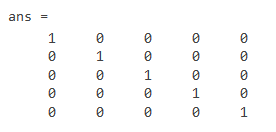

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

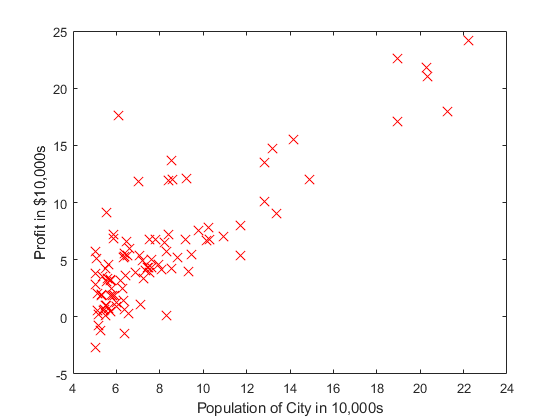

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

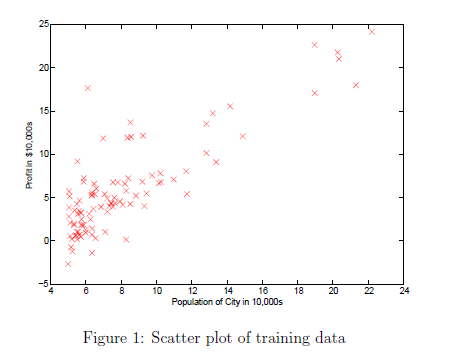

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

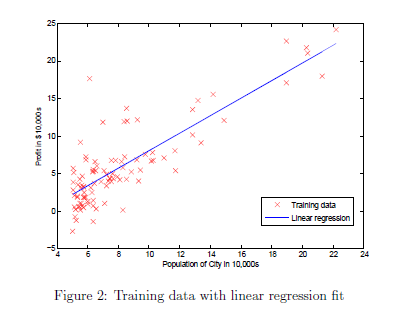    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.630291,
1.166362

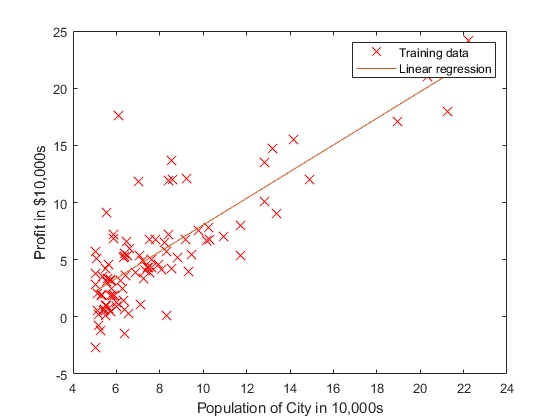


% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure


% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 4519.767868


predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 45342.450129


    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

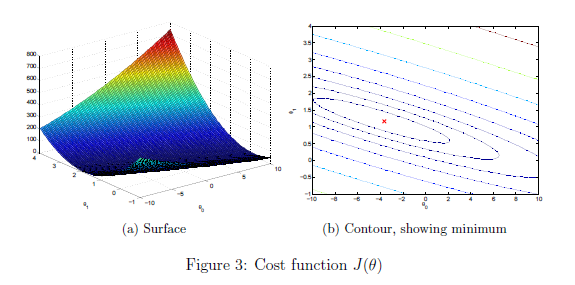

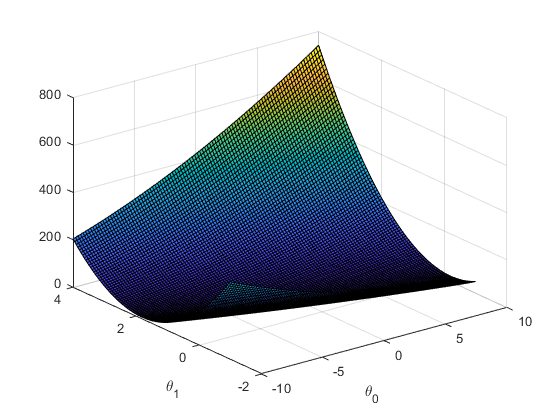

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

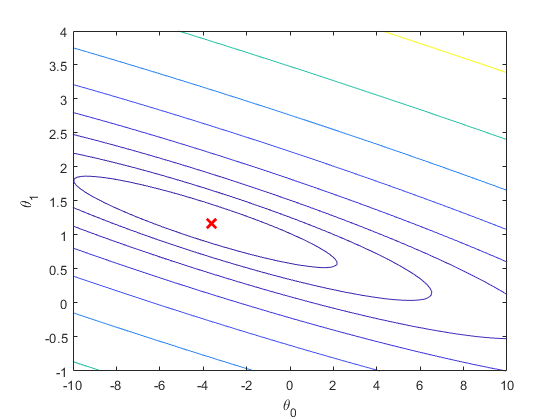


% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

predict =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


s = 	1.0e+06 *

   -0.3999   -0.0520    0.0894
   -0.3299    0.1663    0.0738
   -0.3690   -0.1854    0.0825
   -0.2320    0.1707    0.3568
   -0.5399   -0.6789   -0.5887
   -0.2999    0.0059   -0.3270
   -0.3149    0.1849    0.0704
   -0.1990    0.1437    0.0445
   -0.2120    0.1656    0.0474
   -0.2425    0.1546    0.0542


predict = 	1.0e+04 *

    3.4191
    2.7555
    3.8088
    1.8020
    5.3100
    3.9737
    2.6686
    2.5277
    2.4659
    2.6160


s = 	1.0e+06 *

   -0.3657   -0.0475    0.0818
   -0.3023    0.1524    0.0676
   -0.3309   -0.1663    0.0740
   -0.2140    0.1574    0.3291
   -0.4868   -0.6121   -0.5308
   -0.2602    0.0051   -0.2837
   -0.2882    0.1693    0.0645
   -0.1737    0.1254    0.0389
   -0.1873    0.1463    0.0419
   -0.2163    0.1379    0.0484


predict = 	1.0e+05 *

    0.6505
    0.5262
    0.7236
    0.3530
    0.9993
    0.7489
    0.5099
    0.4835
    0.4719
    0.5000


s = 	1.0e+06 *

   -0.3348   -0.0435    0.0749
   -0.2773    0.1398    0.0620
   -0.2966   -0.1491    0.0664
   -0.1967    0.1447    0.3025
   -0.4400   -0.5532   -0.4797
   -0.2250    0.0044   -0.2454
   -0.2639    0.1550    0.0590
   -0.1506    0.1088    0.0337
   -0.1648    0.1287    0.0369
   -0.1925    0.1227    0.0431


predict = 	1.0e+05 *

    0.9291
    0.7540
    1.0320
    0.5178
    1.4127
    1.0600
    0.7310
    0.6938
    0.6775
    0.7171


s = 	1.0e+06 *

   -0.3070   -0.0399    0.0687
   -0.2545    0.1283    0.0569
   -0.2658   -0.1336    0.0595
   -0.1802    0.1326    0.2771
   -0.3986   -0.5013   -0.4347
   -0.1939    0.0038   -0.2114
   -0.2418    0.1420    0.0541
   -0.1296    0.0936    0.0290
   -0.1443    0.1127    0.0323
   -0.1708    0.1089    0.0382


predict = 	1.0e+05 *

    1.1806
    0.9608
    1.3097
    0.6739
    1.7780
    1.3353
    0.9320
    0.8853
    0.8648
    0.9145


s = 	1.0e+06 *

   -0.2818   -0.0366    0.0630
   -0.2338    0.1179    0.0523
   -0.2380   -0.1196    0.0532
   -0.1646    0.1211    0.2531
   -0.3621   -0.4553   -0.3948
   -0.1664    0.0033   -0.1814
   -0.2217    0.1302    0.0496
   -0.1105    0.0797    0.0247
   -0.1255    0.0980    0.0281
   -0.1510    0.0963    0.0338


predict = 	1.0e+05 *

    1.4076
    1.1484
    1.5598
    0.8212
    2.1009
    1.5789
    1.1144
    1.0594
    1.0352
    1.0939


s = 	1.0e+06 *

   -0.2591   -0.0337    0.0580
   -0.2151    0.1084    0.0481
   -0.2130   -0.1070    0.0476
   -0.1499    0.1103    0.2305
   -0.3298   -0.4147   -0.3596
   -0.1420    0.0028   -0.1548
   -0.2035    0.1195    0.0455
   -0.0931    0.0672    0.0208
   -0.1085    0.0847    0.0243
   -0.1331    0.0849    0.0298


predict = 	1.0e+05 *

    1.6125
    1.3185
    1.7852
    0.9596
    2.3867
    1.7946
    1.2800
    1.2175
    1.1901
    1.2566


s = 	1.0e+06 *

   -0.2386   -0.0310    0.0534
   -0.1981    0.0999    0.0443
   -0.1905   -0.0957    0.0426
   -0.1360    0.1001    0.2092
   -0.3012   -0.3788   -0.3285
   -0.1204    0.0024   -0.1313
   -0.1869    0.1098    0.0418
   -0.0772    0.0558    0.0173
   -0.0930    0.0726    0.0208
   -0.1168    0.0745    0.0261


predict = 	1.0e+05 *

    1.7975
    1.4726
    1.9884
    1.0893
    2.6398
    1.9854
    1.4300
    1.3610
    1.3307
    1.4042


s = 	1.0e+05 *

   -2.2015   -0.2862    0.4924
   -1.8264    0.9209    0.4085
   -1.7016   -0.8550    0.3806
   -1.2307    0.9054    1.8925
   -2.7592   -3.4696   -3.0086
   -1.0136    0.0200   -1.1052
   -1.7190    1.0095    0.3845
   -0.6290    0.4540    0.1407
   -0.7893    0.6165    0.1765
   -1.0208    0.6508    0.2283


predict = 	1.0e+05 *

    1.9646
    1.6121
    2.1716
    1.2104
    2.8642
    2.1543
    1.5659
    1.4911
    1.4582
    1.5379


s = 	1.0e+05 *

   -2.0344   -0.2645    0.4551
   -1.6869    0.8505    0.3773
   -1.5184   -0.7630    0.3396
   -1.1096    0.8163    1.7063
   -2.5348   -3.1875   -2.7640
   -0.8447    0.0167   -0.9211
   -1.5831    0.9297    0.3541
   -0.4989    0.3602    0.1116
   -0.6618    0.5169    0.1480
   -0.8871    0.5656    0.1984


predict = 	1.0e+05 *

    2.1154
    1.7383
    2.3369
    1.3233
    3.0632
    2.3037
    1.6889
    1.6088
    1.5736
    1.6589


s = 	1.0e+05 *

   -1.8836   -0.2449    0.4213
   -1.5607    0.7869    0.3491
   -1.3531   -0.6799    0.3027
   -0.9967    0.7333    1.5328
   -2.3358   -2.9372   -2.5470
   -0.6953    0.0137   -0.7582
   -1.4601    0.8574    0.3266
   -0.3812    0.2752    0.0853
   -0.5464    0.4267    0.1222
   -0.7661    0.4884    0.1713


predict = 	1.0e+05 *

    2.2516
    1.8524
    2.4861
    1.4281
    3.2399
    2.4358
    1.8001
    1.7153
    1.6781
    1.7684


s = 	1.0e+05 *

   -1.7474   -0.2272    0.3908
   -1.4466    0.7294    0.3236
   -1.2039   -0.6049    0.2693
   -0.8919    0.6562    1.3715
   -2.1591   -2.7150   -2.3543
   -0.5632    0.0111   -0.6141
   -1.3489    0.7921    0.3017
   -0.2747    0.1983    0.0614
   -0.4419    0.3451    0.0988
   -0.6566    0.4186    0.1469


predict = 	1.0e+05 *

    2.3747
    1.9555
    2.6208
    1.5254
    3.3969
    2.5527
    1.9006
    1.8116
    1.7725
    1.8673


s = 	1.0e+05 *

   -1.6243   -0.2112    0.3633
   -1.3435    0.6774    0.3005
   -1.0692   -0.5372    0.2391
   -0.7946    0.5846    1.2218
   -2.0021   -2.5176   -2.1832
   -0.4463    0.0088   -0.4867
   -1.2484    0.7331    0.2792
   -0.1784    0.1288    0.0399
   -0.3475    0.2714    0.0777
   -0.5577    0.3556    0.1247


predict = 	1.0e+05 *

    2.4858
    2.0486
    2.7425
    1.6156
    3.5364
    2.6560
    1.9914
    1.8985
    1.8578
    1.9567


s = 	1.0e+05 *

   -1.5132   -0.1967    0.3385
   -1.2504    0.6304    0.2797
   -0.9475   -0.4761    0.2119
   -0.7044    0.5183    1.0832
   -1.8626   -2.3422   -2.0310
   -0.3430    0.0068   -0.3740
   -1.1576    0.6798    0.2589
   -0.0915    0.0660    0.0205
   -0.2622    0.2048    0.0587
   -0.4683    0.2986    0.1048


predict = 	1.0e+05 *

    2.5862
    2.1327
    2.8525
    1.6990
    3.6606
    2.7472
    2.0733
    1.9770
    1.9347
    2.0373


s = 	1.0e+05 *

   -1.4128   -0.1837    0.3160
   -1.1663    0.5881    0.2609
   -0.8375   -0.4208    0.1873
   -0.6210    0.4569    0.9550
   -1.7384   -2.1860   -1.8956
   -0.2518    0.0050   -0.2745
   -1.0757    0.6317    0.2406
   -0.0130    0.0094    0.0029
   -0.1853    0.1447    0.0414
   -0.3877    0.2472    0.0867


predict = 	1.0e+05 *

    2.6769
    2.2085
    2.9520
    1.7760
    3.7711
    2.8278
    2.1471
    2.0477
    2.0040
    2.1100


s = 	1.0e+05 *

   -1.3221   -0.1719    0.2957
   -1.0905    0.5498    0.2439
   -0.7380   -0.3708    0.1651
   -0.5440    0.4003    0.8366
   -1.6279   -2.0470   -1.7751
   -0.1712    0.0034   -0.1867
   -1.0019    0.5883    0.2241
    0.0577   -0.0417   -0.0129
   -0.1160    0.0906    0.0259
   -0.3150    0.2009    0.0705


predict = 	1.0e+05 *

    2.7588
    2.2768
    3.0419
    1.8470
    3.8696
    2.8989
    2.2137
    2.1114
    2.0665
    2.1755


s = 	1.0e+05 *

   -1.2402   -0.1612    0.2774
   -1.0222    0.5154    0.2286
   -0.6481   -0.3256    0.1450
   -0.4730    0.3480    0.7273
   -1.5294   -1.9232   -1.6677
   -0.1001    0.0020   -0.1092
   -0.9353    0.5492    0.2092
    0.1214   -0.0876   -0.0272
   -0.0535    0.0418    0.0120
   -0.2495    0.1591    0.0558


predict = 	1.0e+05 *

    2.8329
    2.3385
    3.1233
    1.9126
    3.9574
    2.9616
    2.2737
    2.1687
    2.1226
    2.2345


s = 	1.0e+05 *

   -1.1661   -0.1516    0.2608
   -0.9605    0.4843    0.2148
   -0.5667   -0.2847    0.1267
   -0.4074    0.2998    0.6266
   -1.4416   -1.8128   -1.5720
   -0.0374    0.0007   -0.0408
   -0.8753    0.5140    0.1958
    0.1787   -0.1290   -0.0400
    0.0026   -0.0020   -0.0006
   -0.1905    0.1215    0.0426


predict = 	1.0e+05 *

    2.8999
    2.3940
    3.1970
    1.9729
    4.0357
    3.0168
    2.3277
    2.2203
    2.1731
    2.2876


s = 	1.0e+05 *

   -1.0991   -0.1429    0.2458
   -0.9050    0.4563    0.2024
   -0.4930   -0.2477    0.1103
   -0.3471    0.2554    0.5337
   -1.3633   -1.7143   -1.4866
    0.0178   -0.0004    0.0194
   -0.8213    0.4823    0.1837
    0.2303   -0.1663   -0.0515
    0.0531   -0.0415   -0.0119
   -0.1374    0.0876    0.0307


predict = 	1.0e+05 *

    2.9605
    2.4439
    3.2638
    2.0285
    4.1056
    3.0654
    2.3763
    2.2666
    2.2185
    2.3353


s = 	1.0e+05 *

   -1.0385   -0.1350    0.2323
   -0.8551    0.4311    0.1913
   -0.4262   -0.2141    0.0953
   -0.2915    0.2145    0.4483
   -1.2934   -1.6264   -1.4103
    0.0664   -0.0013    0.0724
   -0.7727    0.4538    0.1728
    0.2766   -0.1997   -0.0619
    0.0985   -0.0769   -0.0220
   -0.0897    0.0572    0.0201


predict = 	1.0e+05 *

    3.0152
    2.4889
    3.3243
    2.0796
    4.1681
    3.1081
    2.4200
    2.3082
    2.2591
    2.3782


s = 	1.0e+05 *

   -0.9838   -0.1279    0.2200
   -0.8101    0.4085    0.1812
   -0.3657   -0.1837    0.0818
   -0.2404    0.1769    0.3697
   -1.2309   -1.5479   -1.3422
    0.1091   -0.0022    0.1189
   -0.7290    0.4281    0.1631
    0.3182   -0.2297   -0.0712
    0.1391   -0.1087   -0.0311
   -0.0468    0.0298    0.0105


predict = 	1.0e+05 *

    3.0648
    2.5293
    3.3792
    2.1266
    4.2239
    3.1456
    2.4592
    2.3455
    2.2956
    2.4167


s = 	1.0e+05 *

   -0.9342   -0.1215    0.2090
   -0.7697    0.3881    0.1722
   -0.3108   -0.1562    0.0695
   -0.1934    0.1423    0.2974
   -1.1751   -1.4777   -1.2814
    0.1466   -0.0029    0.1598
   -0.6898    0.4051    0.1543
    0.3555   -0.2567   -0.0795
    0.1756   -0.1371   -0.0393
   -0.0083    0.0053    0.0019


predict = 	1.0e+05 *

    3.1096
    2.5657
    3.4290
    2.1698
    4.2738
    3.1784
    2.4944
    2.3790
    2.3282
    2.4513


s = 	1.0e+05 *

   -0.8894   -0.1156    0.1989
   -0.7333    0.3697    0.1640
   -0.2610   -0.1311    0.0584
   -0.1502    0.1105    0.2310
   -1.1252   -1.4149   -1.2269
    0.1794   -0.0035    0.1957
   -0.6546    0.3844    0.1464
    0.3890   -0.2808   -0.0870
    0.2082   -0.1626   -0.0466
    0.0263   -0.0167   -0.0059


predict = 	1.0e+05 *

    3.1501
    2.5983
    3.4742
    2.2095
    4.3185
    3.2072
    2.5261
    2.4089
    2.3574
    2.4823


s = 	1.0e+05 *

   -0.8489   -0.1104    0.1899
   -0.7007    0.3533    0.1567
   -0.2158   -0.1084    0.0483
   -0.1105    0.0813    0.1699
   -1.0805   -1.3587   -1.1782
    0.2082   -0.0041    0.2270
   -0.6229    0.3658    0.1393
    0.4189   -0.3024   -0.0937
    0.2374   -0.1855   -0.0531
    0.0573   -0.0365   -0.0128


predict = 	1.0e+05 *

    3.1869
    2.6276
    3.5153
    2.2460
    4.3585
    3.2323
    2.5544
    2.4357
    2.3835
    2.5100


s = 	1.0e+05 *

   -0.8121   -0.1056    0.1817
   -0.6714    0.3385    0.1502
   -0.1747   -0.0878    0.0391
   -0.0740    0.0544    0.1137
   -1.0405   -1.3085   -1.1346
    0.2333   -0.0046    0.2544
   -0.5946    0.3492    0.1330
    0.4457   -0.3217   -0.0997
    0.2635   -0.2058   -0.0589
    0.0850   -0.0542   -0.0190


predict = 	1.0e+05 *

    3.2201
    2.6540
    3.5526
    2.2796
    4.3943
    3.2541
    2.5798
    2.4596
    2.4068
    2.5349


s = 10×3
   -0.7789   -0.1013    0.1742
   -0.6450    0.3252    0.1443
   -0.1374   -0.0690    0.0307
   -0.0404    0.0297    0.0622
   -1.0047   -1.2634   -1.0956
    0.2551   -0.0050    0.2782
   -0.5692    0.3342    0.1273
    0.4696   -0.3390   -0.1050
    0.2868   -0.2240   -0.0642
    0.1099   -0.0701   -0.0246


predict = 10×1
    3.2502
    2.6776
    3.5865
    2.3104
    4.4264
    3.2731
    2.6026
    2.4810
    2.4276
    2.5571


s = 10×3
   -0.7488   -0.0973    0.1675
   -0.6214    0.3133    0.1390
   -0.1035   -0.0520    0.0231
   -0.0096    0.0071    0.0148
   -0.9726   -1.2230   -1.0605
    0.2741   -0.0054    0.2989
   -0.5464    0.3209    0.1222
    0.4910   -0.3545   -0.1098
    0.3076   -0.2402   -0.0688
    0.1321   -0.0842   -0.0296


predict = 10×1
    3.2775
    2.6987
    3.6174
    2.3387
    4.4552
    3.2896
    2.6229
    2.5001
    2.4461
    2.5770


s = 10×3
   -0.7215   -0.0938    0.1614
   -0.6003    0.3026    0.1343
   -0.0726   -0.0365    0.0162
    0.0187   -0.0137   -0.0287
   -0.9438   -1.1868   -1.0291
    0.2906   -0.0057    0.3169
   -0.5261    0.3089    0.1177
    0.5101   -0.3682   -0.1141
    0.3261   -0.2547   -0.0729
    0.1520   -0.0969   -0.0340


predict = 10×1
    3.3023
    2.7177
    3.6456
    2.3647
    4.4811
    3.3038
    2.6411
    2.5170
    2.4625
    2.5947


s = 10×3
   -0.6967   -0.0906    0.1558
   -0.5813    0.2931    0.1300
   -0.0444   -0.0223    0.0099
    0.0447   -0.0329   -0.0687
   -0.9179   -1.1543   -1.0009
    0.3048   -0.0060    0.3324
   -0.5079    0.2982    0.1136
    0.5270   -0.3805   -0.1179
    0.3425   -0.2675   -0.0766
    0.1697   -0.1082   -0.0380


predict = 10×1
    3.3247
    2.7347
    3.6712
    2.3886
    4.5043
    3.3160
    2.6574
    2.5321
    2.4771
    2.6106


s = 10×3
   -0.6743   -0.0877    0.1508
   -0.5643    0.2845    0.1262
   -0.0188   -0.0094    0.0042
    0.0686   -0.0505   -0.1055
   -0.8947   -1.1251   -0.9756
    0.3170   -0.0063    0.3457
   -0.4916    0.2887    0.1100
    0.5422   -0.3914   -0.1213
    0.3571   -0.2789   -0.0799
    0.1856   -0.1183   -0.0415


predict = 10×1
    3.3450
    2.7499
    3.6946
    2.4106
    4.5251
    3.3265
    2.6719
    2.5456
    2.4901
    2.6247


s = 10×3
   -0.6540   -0.0850    0.1463
   -0.5491    0.2769    0.1228
    0.0046    0.0023   -0.0010
    0.0906   -0.0666   -0.1393
   -0.8739   -1.0989   -0.9529
    0.3275   -0.0065    0.3571
   -0.4771    0.2802    0.1067
    0.5556   -0.4011   -0.1243
    0.3701   -0.2890   -0.0828
    0.1997   -0.1273   -0.0447


predict = 10×1
    3.3635
    2.7634
    3.7159
    2.4308
    4.5438
    3.3354
    2.6849
    2.5575
    2.5015
    2.6372


s = 10×3
   -0.6355   -0.0826    0.1421
   -0.5356    0.2700    0.1198
    0.0259    0.0130   -0.0058
    0.1108   -0.0815   -0.1704
   -0.8552   -1.0753   -0.9325
    0.3364   -0.0066    0.3668
   -0.4641    0.2726    0.1038
    0.5675   -0.4097   -0.1269
    0.3815   -0.2980   -0.0853
    0.2122   -0.1353   -0.0475


predict = 10×1
    3.3803
    2.7756
    3.7354
    2.4494
    4.5607
    3.3429
    2.6964
    2.5680
    2.5116
    2.6484


s = 10×3
   -0.6187   -0.0804    0.1384
   -0.5234    0.2639    0.1171
    0.0454    0.0228   -0.0102
    0.1294   -0.0952   -0.1989
   -0.8383   -1.0541   -0.9141
    0.3439   -0.0068    0.3750
   -0.4526    0.2658    0.1012
    0.5780   -0.4173   -0.1293
    0.3916   -0.3059   -0.0876
    0.2234   -0.1424   -0.0500


predict = 10×1
    3.3955
    2.7864
    3.7532
    2.4665
    4.5759
    3.3493
    2.7067
    2.5774
    2.5206
    2.6583


s = 10×3
   -0.6035   -0.0785    0.1350
   -0.5126    0.2584    0.1147
    0.0632    0.0318   -0.0141
    0.1465   -0.1078   -0.2252
   -0.8231   -1.0351   -0.8976
    0.3503   -0.0069    0.3819
   -0.4423    0.2598    0.0989
    0.5874   -0.4240   -0.1314
    0.4006   -0.3128   -0.0896
    0.2333   -0.1488   -0.0522


predict = 10×1
    3.4093
    2.7961
    3.7695
    2.4822
    4.5895
    3.3545
    2.7158
    2.5856
    2.5284
    2.6671


s = 10×3
   -0.5897   -0.0767    0.1319
   -0.5029    0.2536    0.1125
    0.0795    0.0399   -0.0178
    0.1622   -0.1193   -0.2494
   -0.8095   -1.0179   -0.8827
    0.3555   -0.0070    0.3877
   -0.4332    0.2544    0.0969
    0.5956   -0.4300   -0.1332
    0.4084   -0.3190   -0.0914
    0.2421   -0.1544   -0.0542


predict = 10×1
    3.4219
    2.8047
    3.7844
    2.4967
    4.6018
    3.3588
    2.7239
    2.5929
    2.5353
    2.6749


s = 10×3
   -0.5771   -0.0750    0.1291
   -0.4943    0.2492    0.1106
    0.0944    0.0474   -0.0211
    0.1767   -0.1300   -0.2717
   -0.7972   -1.0025   -0.8693
    0.3598   -0.0071    0.3924
   -0.4251    0.2496    0.0951
    0.6029   -0.4352   -0.1348
    0.4153   -0.3244   -0.0929
    0.2499   -0.1593   -0.0559


predict = 10×1
    3.4333
    2.8124
    3.7980
    2.5101
    4.6129
    3.3623
    2.7311
    2.5992
    2.5413
    2.6818


s = 10×3
   -0.5657   -0.0735    0.1265
   -0.4866    0.2453    0.1088
    0.1080    0.0543   -0.0242
    0.1901   -0.1398   -0.2923
   -0.7861   -0.9885   -0.8572
    0.3633   -0.0072    0.3962
   -0.4179    0.2454    0.0935
    0.6092   -0.4398   -0.1363
    0.4213   -0.3291   -0.0942
    0.2568   -0.1637   -0.0574


predict = 10×1
    3.4438
    2.8192
    3.8105
    2.5224
    4.6229
    3.3651
    2.7374
    2.6048
    2.5466
    2.6879


s = 10×3
   -0.5552   -0.0722    0.1242
   -0.4798    0.2419    0.1073
    0.1205    0.0606   -0.0270
    0.2024   -0.1489   -0.3112
   -0.7761   -0.9760   -0.8463
    0.3661   -0.0072    0.3992
   -0.4116    0.2417    0.0921
    0.6148   -0.4438   -0.1375
    0.4266   -0.3332   -0.0954
    0.2629   -0.1676   -0.0588


predict = 10×1
    3.4532
    2.8253
    3.8220
    2.5337
    4.6319
    3.3673
    2.7430
    2.6097
    2.5512
    2.6932


s = 10×3
   -0.5458   -0.0710    0.1221
   -0.4737    0.2388    0.1060
    0.1320    0.0663   -0.0295
    0.2137   -0.1572   -0.3287
   -0.7671   -0.9646   -0.8365
    0.3683   -0.0073    0.4016
   -0.4060    0.2384    0.0908
    0.6197   -0.4474   -0.1386
    0.4312   -0.3368   -0.0964
    0.2682   -0.1710   -0.0600


predict = 10×1
    3.4619
    2.8307
    3.8326
    2.5442
    4.6400
    3.3688
    2.7480
    2.6140
    2.5551
    2.6979


s = 10×3
   -0.5371   -0.0698    0.1201
   -0.4683    0.2361    0.1048
    0.1426    0.0716   -0.0319
    0.2242   -0.1650   -0.3448
   -0.7590   -0.9544   -0.8276
    0.3698   -0.0073    0.4033
   -0.4010    0.2355    0.0897
    0.6240   -0.4505   -0.1396
    0.4351   -0.3399   -0.0973
    0.2729   -0.1740   -0.0610


predict = 10×1
    3.4697
    2.8354
    3.8423
    2.5539
    4.6474
    3.3700
    2.7524
    2.6177
    2.5586
    2.7020


s = 10×3
   -0.5293   -0.0688    0.1184
   -0.4636    0.2337    0.1037
    0.1523    0.0765   -0.0341
    0.2339   -0.1721   -0.3597
   -0.7516   -0.9452   -0.8196
    0.3710   -0.0073    0.4045
   -0.3966    0.2329    0.0887
    0.6277   -0.4531   -0.1404
    0.4386   -0.3425   -0.0981
    0.2770   -0.1766   -0.0620


predict = 10×1
    3.4769
    2.8397
    3.8512
    2.5628
    4.6540
    3.3706
    2.7562
    2.6209
    2.5615
    2.7056


s = 10×3
   -0.5221   -0.0679    0.1168
   -0.4593    0.2316    0.1027
    0.1612    0.0810   -0.0361
    0.2428   -0.1787   -0.3734
   -0.7450   -0.9368   -0.8124
    0.3716   -0.0073    0.4052
   -0.3928    0.2307    0.0879
    0.6309   -0.4555   -0.1411
    0.4415   -0.3448   -0.0988
    0.2806   -0.1789   -0.0628


predict = 10×1
    3.4835
    2.8434
    3.8594
    2.5711
    4.6600
    3.3710
    2.7596
    2.6237
    2.5640
    2.7088


s = 10×3
   -0.5155   -0.0670    0.1153
   -0.4556    0.2297    0.1019
    0.1694    0.0851   -0.0379
    0.2511   -0.1848   -0.3862
   -0.7390   -0.9293   -0.8058
    0.3720   -0.0073    0.4056
   -0.3894    0.2287    0.0871
    0.6337   -0.4575   -0.1417
    0.4440   -0.3468   -0.0993
    0.2838   -0.1809   -0.0635


predict = 10×1
    3.4895
    2.8467
    3.8670
    2.5788
    4.6654
    3.3710
    2.7625
    2.6261
    2.5661
    2.7115


s = 10×3
   -0.5095   -0.0662    0.1140
   -0.4523    0.2280    0.1012
    0.1770    0.0889   -0.0396
    0.2588   -0.1904   -0.3979
   -0.7336   -0.9224   -0.7999
    0.3720   -0.0073    0.4056
   -0.3865    0.2269    0.0864
    0.6361   -0.4592   -0.1423
    0.4461   -0.3484   -0.0998
    0.2865   -0.1827   -0.0641


predict = 10×1
    3.4949
    2.8496
    3.8740
    2.5859
    4.6704
    3.3707
    2.7651
    2.6281
    2.5679
    2.7139


s = 10×3
   -0.5041   -0.0655    0.1127
   -0.4494    0.2266    0.1005
    0.1840    0.0924   -0.0411
    0.2659   -0.1956   -0.4088
   -0.7286   -0.9162   -0.7945
    0.3717   -0.0073    0.4053
   -0.3839    0.2254    0.0859
    0.6381   -0.4606   -0.1427
    0.4479   -0.3498   -0.1002
    0.2889   -0.1842   -0.0646


predict = 10×1
    3.5000
    2.8522
    3.8804
    2.5924
    4.6748
    3.3702
    2.7673
    2.6298
    2.5694
    2.7159


s = 10×3
   -0.4990   -0.0649    0.1116
   -0.4468    0.2253    0.0999
    0.1904    0.0957   -0.0426
    0.2724   -0.2004   -0.4190
   -0.7242   -0.9106   -0.7897
    0.3712   -0.0073    0.4048
   -0.3817    0.2241    0.0854
    0.6398   -0.4619   -0.1431
    0.4494   -0.3510   -0.1005
    0.2909   -0.1855   -0.0651


predict = 10×1
    3.5045
    2.8544
    3.8864
    2.5985
    4.6788
    3.3696
    2.7693
    2.6312
    2.5706
    2.7177


s = 10×3
   -0.4945   -0.0643    0.1106
   -0.4446    0.2242    0.0994
    0.1964    0.0987   -0.0439
    0.2785   -0.2049   -0.4283
   -0.7202   -0.9056   -0.7853
    0.3706   -0.0073    0.4041
   -0.3797    0.2230    0.0849
    0.6413   -0.4629   -0.1434
    0.4506   -0.3519   -0.1008
    0.2927   -0.1866   -0.0655


predict = 10×1
    3.5087
    2.8564
    3.8919
    2.6042
    4.6825
    3.3687
    2.7709
    2.6324
    2.5716
    2.7192


s = 10×3
   -0.4903   -0.0637    0.1097
   -0.4426    0.2232    0.0990
    0.2019    0.1014   -0.0452
    0.2842   -0.2091   -0.4370
   -0.7165   -0.9010   -0.7813
    0.3697   -0.0073    0.4031
   -0.3781    0.2220    0.0846
    0.6424   -0.4638   -0.1437
    0.4516   -0.3527   -0.1010
    0.2942   -0.1875   -0.0658


predict = 10×1
    3.5126
    2.8581
    3.8970
    2.6095
    4.6858
    3.3677
    2.7724
    2.6334
    2.5724
    2.7204


s = 10×3
   -0.4864   -0.0632    0.1088
   -0.4409    0.2223    0.0986
    0.2070    0.1040   -0.0463
    0.2895   -0.2130   -0.4451
   -0.7132   -0.8968   -0.7777
    0.3687   -0.0073    0.4021
   -0.3766    0.2212    0.0842
    0.6434   -0.4645   -0.1439
    0.4524   -0.3533   -0.1012
    0.2954   -0.1884   -0.0661


predict = 10×1
    3.5161
    2.8596
    3.9017
    2.6144
    4.6888
    3.3666
    2.7736
    2.6342
    2.5730
    2.7215


s = 10×3
   -0.4829   -0.0628    0.1080
   -0.4394    0.2216    0.0983
    0.2117    0.1064   -0.0474
    0.2944   -0.2166   -0.4526
   -0.7102   -0.8930   -0.7744
    0.3676   -0.0073    0.4009
   -0.3754    0.2205    0.0840
    0.6442   -0.4650   -0.1441
    0.4530   -0.3538   -0.1013
    0.2965   -0.1890   -0.0663


predict = 10×1
    3.5194
    2.8609
    3.9061
    2.6189
    4.6916
    3.3654
    2.7746
    2.6348
    2.5734
    2.7224


s = 10×3
   -0.4796   -0.0624    0.1073
   -0.4381    0.2209    0.0980
    0.2161    0.1086   -0.0483
    0.2989   -0.2199   -0.4596
   -0.7074   -0.8896   -0.7714
    0.3664   -0.0072    0.3996
   -0.3744    0.2199    0.0837
    0.6448   -0.4655   -0.1442
    0.4534   -0.3541   -0.1014
    0.2974   -0.1896   -0.0665


predict = 10×1
    3.5223
    2.8620
    3.9102
    2.6231
    4.6941
    3.3642
    2.7755
    2.6353
    2.5737
    2.7231


s = 10×3
   -0.4767   -0.0620    0.1066
   -0.4370    0.2203    0.0978
    0.2202    0.1106   -0.0492
    0.3031   -0.2230   -0.4662
   -0.7049   -0.8864   -0.7687
    0.3652   -0.0072    0.3982
   -0.3735    0.2193    0.0835
    0.6453   -0.4658   -0.1443
    0.4537   -0.3544   -0.1015
    0.2981   -0.1900   -0.0667


predict = 10×1
    3.5251
    2.8629
    3.9140
    2.6271
    4.6964
    3.3628
    2.7762
    2.6356
    2.5739
    2.7237


s = 10×3
   -0.4739   -0.0616    0.1060
   -0.4361    0.2199    0.0975
    0.2240    0.1125   -0.0501
    0.3071   -0.2259   -0.4722
   -0.7026   -0.8836   -0.7662
    0.3638   -0.0072    0.3967
   -0.3728    0.2189    0.0834
    0.6456   -0.4661   -0.1444
    0.4539   -0.3545   -0.1015
    0.2987   -0.1904   -0.0668


predict = 10×1
    3.5276
    2.8637
    3.9175
    2.6308
    4.6984
    3.3615
    2.7768
    2.6359
    2.5740
    2.7241


s = 10×3
   -0.4714   -0.0613    0.1054
   -0.4353    0.2195    0.0974
    0.2275    0.1143   -0.0509
    0.3108   -0.2286   -0.4779
   -0.7006   -0.8810   -0.7639
    0.3625   -0.0072    0.3952
   -0.3722    0.2186    0.0833
    0.6459   -0.4662   -0.1445
    0.4540   -0.3545   -0.1015
    0.2991   -0.1907   -0.0669


predict = 10×1
    3.5299
    2.8644
    3.9208
    2.6342
    4.7003
    3.3601
    2.7773
    2.6360
    2.5739
    2.7245


s = 10×3
   -0.4691   -0.0610    0.1049
   -0.4346    0.2191    0.0972
    0.2308    0.1160   -0.0516
    0.3142   -0.2312   -0.4832
   -0.6987   -0.8786   -0.7619
    0.3611   -0.0071    0.3937
   -0.3717    0.2183    0.0831
    0.6460   -0.4663   -0.1445
    0.4539   -0.3545   -0.1015
    0.2995   -0.1909   -0.0670


predict = 10×1
    3.5321
    2.8650
    3.9238
    2.6374
    4.7020
    3.3586
    2.7777
    2.6360
    2.5738
    2.7247


s = 10×3
   -0.4669   -0.0607    0.1044
   -0.4340    0.2188    0.0971
    0.2338    0.1175   -0.0523
    0.3174   -0.2335   -0.4881
   -0.6970   -0.8764   -0.7600
    0.3596   -0.0071    0.3921
   -0.3713    0.2181    0.0831
    0.6461   -0.4664   -0.1445
    0.4538   -0.3545   -0.1015
    0.2997   -0.1911   -0.0670


predict = 10×1
    3.5341
    2.8655
    3.9267
    2.6404
    4.7036
    3.3572
    2.7780
    2.6360
    2.5737
    2.7249


s = 10×3
   -0.4649   -0.0604    0.1040
   -0.4335    0.2186    0.0970
    0.2367    0.1189   -0.0529
    0.3204   -0.2358   -0.4928
   -0.6954   -0.8745   -0.7583
    0.3582   -0.0071    0.3906
   -0.3710    0.2179    0.0830
    0.6460   -0.4664   -0.1445
    0.4537   -0.3543   -0.1015
    0.2999   -0.1912   -0.0671


predict = 10×1
    3.5359
    2.8659
    3.9294
    2.6433
    4.7050
    3.3557
    2.7782
    2.6359
    2.5734
    2.7250


s = 10×3
   -0.4631   -0.0602    0.1036
   -0.4331    0.2184    0.0969
    0.2394    0.1203   -0.0535
    0.3233   -0.2378   -0.4971
   -0.6940   -0.8727   -0.7567
    0.3567   -0.0070    0.3890
   -0.3708    0.2178    0.0829
    0.6459   -0.4663   -0.1445
    0.4534   -0.3542   -0.1014
    0.3000   -0.1913   -0.0671


predict = 10×1
    3.5376
    2.8662
    3.9319
    2.6459
    4.7063
    3.3543
    2.7783
    2.6358
    2.5732
    2.7250


s = 10×3
   -0.4614   -0.0600    0.1032
   -0.4328    0.2182    0.0968
    0.2419    0.1215   -0.0541
    0.3259   -0.2398   -0.5011
   -0.6927   -0.8710   -0.7553
    0.3553   -0.0070    0.3874
   -0.3707    0.2177    0.0829
    0.6458   -0.4662   -0.1444
    0.4532   -0.3539   -0.1014
    0.3000   -0.1913   -0.0671


predict = 10×1
    3.5391
    2.8665
    3.9342
    2.6484
    4.7075
    3.3529
    2.7784
    2.6356
    2.5729
    2.7250


s = 10×3
   -0.4599   -0.0598    0.1029
   -0.4325    0.2181    0.0967
    0.2442    0.1227   -0.0546
    0.3284   -0.2416   -0.5049
   -0.6915   -0.8695   -0.7540
    0.3539   -0.0070    0.3859
   -0.3706    0.2176    0.0829
    0.6456   -0.4660   -0.1444
    0.4529   -0.3537   -0.1013
    0.3000   -0.1913   -0.0671


predict = 10×1
    3.5406
    2.8667
    3.9364
    2.6507
    4.7086
    3.3514
    2.7784
    2.6354
    2.5725
    2.7250


s = 10×3
   -0.4584   -0.0596    0.1025
   -0.4323    0.2180    0.0967
    0.2464    0.1238   -0.0551
    0.3307   -0.2433   -0.5085
   -0.6904   -0.8681   -0.7528
    0.3524   -0.0070    0.3843
   -0.3706    0.2176    0.0829
    0.6454   -0.4659   -0.1444
    0.4525   -0.3534   -0.1012
    0.3000   -0.1912   -0.0671


predict = 10×1
    3.5419
    2.8668
    3.9384
    2.6529
    4.7096
    3.3500
    2.7784
    2.6351
    2.5721
    2.7248


s = 10×3
   -0.4571   -0.0594    0.1022
   -0.4322    0.2179    0.0967
    0.2484    0.1248   -0.0556
    0.3329   -0.2449   -0.5119
   -0.6894   -0.8669   -0.7517
    0.3510   -0.0069    0.3828
   -0.3706    0.2176    0.0829
    0.6451   -0.4657   -0.1443
    0.4521   -0.3531   -0.1011
    0.2998   -0.1912   -0.0671


predict = 10×1
    3.5432
    2.8669
    3.9403
    2.6549
    4.7105
    3.3487
    2.7784
    2.6348
    2.5718
    2.7247


s = 10×3
   -0.4558   -0.0593    0.1020
   -0.4321    0.2178    0.0966
    0.2503    0.1258   -0.0560
    0.3349   -0.2464   -0.5150
   -0.6885   -0.8657   -0.7507
    0.3497   -0.0069    0.3813
   -0.3706    0.2176    0.0829
    0.6448   -0.4655   -0.1442
    0.4518   -0.3528   -0.1010
    0.2997   -0.1911   -0.0670


predict = 10×1
    3.5443
    2.8670
    3.9421
    2.6568
    4.7114
    3.3473
    2.7783
    2.6345
    2.5713
    2.7245


s = 10×3
   -0.4547   -0.0591    0.1017
   -0.4320    0.2178    0.0966
    0.2521    0.1267   -0.0564
    0.3368   -0.2478   -0.5180
   -0.6876   -0.8647   -0.7498
    0.3483   -0.0069    0.3798
   -0.3707    0.2177    0.0829
    0.6445   -0.4653   -0.1442
    0.4513   -0.3525   -0.1010
    0.2995   -0.1910   -0.0670


predict = 10×1
    3.5454
    2.8670
    3.9438
    2.6586
    4.7122
    3.3460
    2.7782
    2.6342
    2.5709
    2.7244


s = 10×3
   -0.4536   -0.0590    0.1015
   -0.4320    0.2178    0.0966
    0.2538    0.1275   -0.0568
    0.3386   -0.2491   -0.5208
   -0.6868   -0.8637   -0.7489
    0.3470   -0.0068    0.3783
   -0.3708    0.2178    0.0829
    0.6442   -0.4650   -0.1441
    0.4509   -0.3522   -0.1009
    0.2994   -0.1909   -0.0670


predict = 10×1
    3.5464
    2.8670
    3.9454
    2.6604
    4.7129
    3.3447
    2.7781
    2.6338
    2.5705
    2.7241


s = 10×3
   -0.4526   -0.0588    0.1012
   -0.4320    0.2178    0.0966
    0.2554    0.1283   -0.0571
    0.3404   -0.2504   -0.5234
   -0.6861   -0.8628   -0.7482
    0.3457   -0.0068    0.3769
   -0.3709    0.2178    0.0830
    0.6438   -0.4648   -0.1440
    0.4505   -0.3518   -0.1008
    0.2991   -0.1907   -0.0669


predict = 10×1
    3.5474
    2.8670
    3.9469
    2.6620
    4.7135
    3.3434
    2.7779
    2.6335
    2.5700
    2.7239


s = 10×3
   -0.4516   -0.0587    0.1010
   -0.4320    0.2178    0.0966
    0.2569    0.1291   -0.0575
    0.3420   -0.2516   -0.5259
   -0.6855   -0.8620   -0.7474
    0.3444   -0.0068    0.3755
   -0.3711    0.2179    0.0830
    0.6435   -0.4645   -0.1439
    0.4500   -0.3515   -0.1007
    0.2989   -0.1906   -0.0669


predict = 10×1
    3.5482
    2.8670
    3.9483
    2.6635
    4.7141
    3.3422
    2.7778
    2.6331
    2.5696
    2.7237


s = 10×3
   -0.4508   -0.0586    0.1008
   -0.4320    0.2178    0.0966
    0.2583    0.1298   -0.0578
    0.3435   -0.2527   -0.5282
   -0.6849   -0.8612   -0.7468
    0.3432   -0.0068    0.3742
   -0.3712    0.2180    0.0830
    0.6431   -0.4643   -0.1439
    0.4496   -0.3511   -0.1006
    0.2987   -0.1904   -0.0668


predict = 10×1
    3.5490
    2.8669
    3.9497
    2.6649
    4.7147
    3.3409
    2.7776
    2.6328
    2.5691
    2.7234


s = 10×3
   -0.4500   -0.0585    0.1006
   -0.4321    0.2179    0.0966
    0.2597    0.1305   -0.0581
    0.3449   -0.2538   -0.5304
   -0.6843   -0.8605   -0.7462
    0.3419   -0.0067    0.3729
   -0.3714    0.2181    0.0831
    0.6428   -0.4640   -0.1438
    0.4491   -0.3508   -0.1005
    0.2984   -0.1903   -0.0668


predict = 10×1
    3.5498
    2.8668
    3.9509
    2.6663
    4.7152
    3.3398
    2.7774
    2.6324
    2.5687
    2.7232


s = 10×3
   -0.4492   -0.0584    0.1005
   -0.4322    0.2179    0.0967
    0.2609    0.1311   -0.0584
    0.3463   -0.2547   -0.5325
   -0.6838   -0.8598   -0.7456
    0.3408   -0.0067    0.3716
   -0.3716    0.2182    0.0831
    0.6424   -0.4637   -0.1437
    0.4487   -0.3504   -0.1004
    0.2982   -0.1901   -0.0667


predict = 10×1
    3.5505
    2.8667
    3.9521
    2.6675
    4.7157
    3.3386
    2.7772
    2.6320
    2.5683
    2.7229


s = 10×3
   -0.4485   -0.0583    0.1003
   -0.4323    0.2179    0.0967
    0.2621    0.1317   -0.0586
    0.3475   -0.2557   -0.5344
   -0.6833   -0.8592   -0.7451
    0.3396   -0.0067    0.3703
   -0.3718    0.2183    0.0832
    0.6420   -0.4635   -0.1436
    0.4483   -0.3501   -0.1003
    0.2979   -0.1899   -0.0666


predict = 10×1
    3.5512
    2.8666
    3.9532
    2.6687
    4.7161
    3.3375
    2.7770
    2.6317
    2.5678
    2.7227


s = 10×3
   -0.4478   -0.0582    0.1002
   -0.4324    0.2180    0.0967
    0.2632    0.1323   -0.0589
    0.3487   -0.2566   -0.5363
   -0.6829   -0.8587   -0.7446
    0.3385   -0.0067    0.3691
   -0.3720    0.2185    0.0832
    0.6417   -0.4632   -0.1435
    0.4478   -0.3498   -0.1002
    0.2977   -0.1898   -0.0666


predict = 10×1
    3.5518
    2.8665
    3.9543
    2.6699
    4.7165
    3.3365
    2.7768
    2.6313
    2.5674
    2.7224


s = 10×3
   -0.4472   -0.0581    0.1000
   -0.4325    0.2181    0.0967
    0.2643    0.1328   -0.0591
    0.3499   -0.2574   -0.5380
   -0.6825   -0.8582   -0.7442
    0.3375   -0.0067    0.3680
   -0.3722    0.2186    0.0833
    0.6413   -0.4629   -0.1434
    0.4474   -0.3494   -0.1001
    0.2974   -0.1896   -0.0665


predict = 10×1
    3.5524
    2.8664
    3.9553
    2.6710
    4.7169
    3.3354
    2.7766
    2.6309
    2.5670
    2.7221


s = 10×3
   -0.4466   -0.0581    0.0999
   -0.4326    0.2181    0.0968
    0.2653    0.1333   -0.0593
    0.3510   -0.2582   -0.5397
   -0.6821   -0.8577   -0.7437
    0.3364   -0.0066    0.3668
   -0.3724    0.2187    0.0833
    0.6409   -0.4627   -0.1434
    0.4470   -0.3491   -0.1000
    0.2971   -0.1894   -0.0665


predict = 10×1
    3.5529
    2.8663
    3.9562
    2.6720
    4.7173
    3.3344
    2.7764
    2.6306
    2.5665
    2.7219


s = 10×3
   -0.4461   -0.0580    0.0998
   -0.4327    0.2182    0.0968
    0.2662    0.1338   -0.0595
    0.3520   -0.2590   -0.5413
   -0.6817   -0.8572   -0.7434
    0.3354   -0.0066    0.3657
   -0.3726    0.2188    0.0834
    0.6406   -0.4624   -0.1433
    0.4465   -0.3488   -0.0999
    0.2969   -0.1893   -0.0664


predict = 10×1
    3.5535
    2.8661
    3.9571
    2.6730
    4.7176
    3.3334
    2.7761
    2.6302
    2.5661
    2.7216


s = 10×3
   -0.4455   -0.0579    0.0997
   -0.4329    0.2182    0.0968
    0.2671    0.1342   -0.0597
    0.3530   -0.2597   -0.5428
   -0.6814   -0.8568   -0.7430
    0.3344   -0.0066    0.3647
   -0.3729    0.2190    0.0834
    0.6402   -0.4622   -0.1432
    0.4461   -0.3484   -0.0998
    0.2966   -0.1891   -0.0663


predict = 10×1
    3.5539
    2.8660
    3.9580
    2.6739
    4.7179
    3.3325
    2.7759
    2.6299
    2.5657
    2.7213


s = 10×3
   -0.4451   -0.0579    0.0996
   -0.4330    0.2183    0.0968
    0.2680    0.1346   -0.0599
    0.3539   -0.2603   -0.5442
   -0.6811   -0.8565   -0.7427
    0.3335   -0.0066    0.3637
   -0.3731    0.2191    0.0834
    0.6399   -0.4619   -0.1431
    0.4457   -0.3481   -0.0997
    0.2963   -0.1889   -0.0663


predict = 10×1
    3.5544
    2.8659
    3.9588
    2.6747
    4.7182
    3.3316
    2.7757
    2.6295
    2.5653
    2.7211


s = 10×3
   -0.4446   -0.0578    0.0994
   -0.4331    0.2184    0.0969
    0.2688    0.1350   -0.0601
    0.3547   -0.2610   -0.5455
   -0.6808   -0.8561   -0.7424
    0.3326   -0.0066    0.3627
   -0.3733    0.2192    0.0835
    0.6395   -0.4617   -0.1431
    0.4453   -0.3478   -0.0996
    0.2961   -0.1888   -0.0662


predict = 10×1
    3.5548
    2.8657
    3.9595
    2.6756
    4.7185
    3.3307
    2.7755
    2.6292
    2.5649
    2.7208


s = 10×3
   -0.4442   -0.0577    0.0994
   -0.4333    0.2184    0.0969
    0.2695    0.1354   -0.0603
    0.3556   -0.2616   -0.5468
   -0.6805   -0.8558   -0.7421
    0.3317   -0.0065    0.3617
   -0.3735    0.2193    0.0835
    0.6392   -0.4614   -0.1430
    0.4449   -0.3475   -0.0995
    0.2958   -0.1886   -0.0662


predict = 10×1
    3.5552
    2.8656
    3.9602
    2.6764
    4.7187
    3.3299
    2.7753
    2.6289
    2.5646
    2.7206


s = 10×3
   -0.4438   -0.0577    0.0993
   -0.4334    0.2185    0.0969
    0.2702    0.1358   -0.0604
    0.3564   -0.2622   -0.5480
   -0.6803   -0.8555   -0.7418
    0.3309   -0.0065    0.3608
   -0.3737    0.2195    0.0836
    0.6389   -0.4612   -0.1429
    0.4446   -0.3472   -0.0994
    0.2956   -0.1884   -0.0661


predict = 10×1
    3.5556
    2.8655
    3.9609
    2.6771
    4.7189
    3.3291
    2.7751
    2.6286
    2.5642
    2.7203


s = 10×3
   -0.4434   -0.0576    0.0992
   -0.4335    0.2186    0.0970
    0.2709    0.1361   -0.0606
    0.3571   -0.2627   -0.5491
   -0.6801   -0.8552   -0.7416
    0.3301   -0.0065    0.3599
   -0.3739    0.2196    0.0836
    0.6386   -0.4610   -0.1428
    0.4442   -0.3469   -0.0994
    0.2953   -0.1883   -0.0661


predict = 10×1
    3.5560
    2.8653
    3.9616
    2.6778
    4.7191
    3.3283
    2.7749
    2.6283
    2.5639
    2.7201


s = 10×3
   -0.4430   -0.0576    0.0991
   -0.4337    0.2187    0.0970
    0.2716    0.1365   -0.0607
    0.3578   -0.2632   -0.5502
   -0.6799   -0.8549   -0.7413
    0.3293   -0.0065    0.3591
   -0.3741    0.2197    0.0837
    0.6383   -0.4608   -0.1428
    0.4439   -0.3467   -0.0993
    0.2951   -0.1881   -0.0660


predict = 10×1
    3.5563
    2.8652
    3.9622
    2.6785
    4.7193
    3.3275
    2.7747
    2.6280
    2.5635
    2.7198


s = 10×3
   -0.4427   -0.0576    0.0990
   -0.4338    0.2187    0.0970
    0.2722    0.1368   -0.0609
    0.3585   -0.2637   -0.5513
   -0.6797   -0.8547   -0.7411
    0.3285   -0.0065    0.3582
   -0.3743    0.2198    0.0837
    0.6380   -0.4605   -0.1427
    0.4435   -0.3464   -0.0992
    0.2948   -0.1880   -0.0659


predict = 10×1
    3.5566
    2.8651
    3.9628
    2.6791
    4.7195
    3.3268
    2.7745
    2.6277
    2.5632
    2.7196


s = 10×3
   -0.4424   -0.0575    0.0990
   -0.4339    0.2188    0.0971
    0.2728    0.1371   -0.0610
    0.3591   -0.2642   -0.5522
   -0.6795   -0.8544   -0.7409
    0.3278   -0.0065    0.3574
   -0.3745    0.2199    0.0838
    0.6377   -0.4603   -0.1426
    0.4432   -0.3461   -0.0991
    0.2946   -0.1878   -0.0659


predict = 10×1
    3.5569
    2.8649
    3.9633
    2.6797
    4.7197
    3.3261
    2.7743
    2.6274
    2.5629
    2.7194


s = 10×3
   -0.4421   -0.0575    0.0989
   -0.4341    0.2189    0.0971
    0.2733    0.1373   -0.0611
    0.3597   -0.2647   -0.5532
   -0.6793   -0.8542   -0.7407
    0.3271   -0.0065    0.3567
   -0.3747    0.2200    0.0838
    0.6374   -0.4601   -0.1426
    0.4429   -0.3459   -0.0991
    0.2944   -0.1877   -0.0658


predict = 10×1
    3.5572
    2.8648
    3.9639
    2.6803
    4.7199
    3.3254
    2.7741
    2.6271
    2.5626
    2.7192


s = 10×3
   -0.4418   -0.0574    0.0988
   -0.4342    0.2189    0.0971
    0.2739    0.1376   -0.0613
    0.3603   -0.2651   -0.5541
   -0.6791   -0.8540   -0.7405
    0.3264   -0.0064    0.3559
   -0.3749    0.2201    0.0839
    0.6371   -0.4599   -0.1425
    0.4426   -0.3456   -0.0990
    0.2942   -0.1876   -0.0658


predict = 10×1
    3.5575
    2.8647
    3.9644
    2.6809
    4.7200
    3.3248
    2.7739
    2.6269
    2.5623
    2.7190


s = 10×3
   -0.4415   -0.0574    0.0988
   -0.4343    0.2190    0.0971
    0.2744    0.1379   -0.0614
    0.3609   -0.2655   -0.5549
   -0.6790   -0.8538   -0.7404
    0.3258   -0.0064    0.3552
   -0.3751    0.2202    0.0839
    0.6369   -0.4597   -0.1425
    0.4423   -0.3454   -0.0989
    0.2940   -0.1874   -0.0658


predict = 10×1
    3.5577
    2.8645
    3.9648
    2.6814
    4.7202
    3.3242
    2.7738
    2.6266
    2.5620
    2.7188


s = 10×3
   -0.4413   -0.0574    0.0987
   -0.4345    0.2190    0.0972
    0.2748    0.1381   -0.0615
    0.3614   -0.2659   -0.5557
   -0.6788   -0.8536   -0.7402
    0.3252   -0.0064    0.3546
   -0.3752    0.2203    0.0839
    0.6366   -0.4596   -0.1424
    0.4420   -0.3452   -0.0989
    0.2938   -0.1873   -0.0657


predict = 10×1
    3.5580
    2.8644
    3.9653
    2.6819
    4.7203
    3.3236
    2.7736
    2.6264
    2.5617
    2.7186


s = 10×3
   -0.4410   -0.0573    0.0986
   -0.4346    0.2191    0.0972
    0.2753    0.1383   -0.0616
    0.3619   -0.2662   -0.5565
   -0.6787   -0.8535   -0.7401
    0.3246   -0.0064    0.3539
   -0.3754    0.2204    0.0840
    0.6364   -0.4594   -0.1423
    0.4417   -0.3450   -0.0988
    0.2936   -0.1872   -0.0657


predict = 10×1
    3.5582
    2.8643
    3.9657
    2.6824
    4.7204
    3.3230
    2.7734
    2.6261
    2.5614
    2.7184


s = 10×3
   -0.4408   -0.0573    0.0986
   -0.4347    0.2192    0.0972
    0.2757    0.1385   -0.0617
    0.3624   -0.2666   -0.5572
   -0.6786   -0.8533   -0.7399
    0.3240   -0.0064    0.3533
   -0.3756    0.2205    0.0840
    0.6361   -0.4592   -0.1423
    0.4414   -0.3448   -0.0987
    0.2934   -0.1870   -0.0656


predict = 10×1
    3.5584
    2.8642
    3.9661
    2.6828
    4.7205
    3.3224
    2.7733
    2.6259
    2.5612
    2.7182


s = 10×3
   -0.4406   -0.0573    0.0985
   -0.4348    0.2192    0.0973
    0.2761    0.1388   -0.0618
    0.3628   -0.2669   -0.5579
   -0.6785   -0.8531   -0.7398
    0.3234   -0.0064    0.3527
   -0.3757    0.2206    0.0840
    0.6359   -0.4590   -0.1422
    0.4412   -0.3446   -0.0987
    0.2932   -0.1869   -0.0656


predict = 10×1
    3.5586
    2.8641
    3.9665
    2.6832
    4.7207
    3.3219
    2.7731
    2.6257
    2.5609
    2.7180


s = 10×3
   -0.4404   -0.0573    0.0985
   -0.4349    0.2193    0.0973
    0.2765    0.1390   -0.0619
    0.3632   -0.2672   -0.5586
   -0.6783   -0.8530   -0.7397
    0.3229   -0.0064    0.3521
   -0.3759    0.2207    0.0841
    0.6357   -0.4589   -0.1422
    0.4409   -0.3444   -0.0986
    0.2930   -0.1868   -0.0655


predict = 10×1
    3.5588
    2.8640
    3.9669
    2.6836
    4.7208
    3.3214
    2.7730
    2.6255
    2.5607
    2.7178


s = 10×3
   -0.4402   -0.0572    0.0985
   -0.4350    0.2193    0.0973
    0.2769    0.1391   -0.0619
    0.3636   -0.2675   -0.5592
   -0.6782   -0.8529   -0.7396
    0.3224   -0.0064    0.3516
   -0.3760    0.2208    0.0841
    0.6355   -0.4587   -0.1421
    0.4407   -0.3442   -0.0986
    0.2928   -0.1867   -0.0655


predict = 10×1
    3.5590
    2.8639
    3.9673
    2.6840
    4.7209
    3.3209
    2.7728
    2.6253
    2.5604
    2.7177


s = 10×3
   -0.4400   -0.0572    0.0984
   -0.4351    0.2194    0.0973
    0.2773    0.1393   -0.0620
    0.3640   -0.2678   -0.5598
   -0.6781   -0.8527   -0.7395
    0.3219   -0.0064    0.3510
   -0.3762    0.2209    0.0841
    0.6353   -0.4586   -0.1421
    0.4404   -0.3440   -0.0985
    0.2927   -0.1866   -0.0655


predict = 10×1
    3.5592
    2.8638
    3.9676
    2.6844
    4.7210
    3.3205
    2.7727
    2.6251
    2.5602
    2.7175


s = 10×3
   -0.4398   -0.0572    0.0984
   -0.4352    0.2194    0.0974
    0.2776    0.1395   -0.0621
    0.3644   -0.2681   -0.5604
   -0.6780   -0.8526   -0.7394
    0.3215   -0.0063    0.3505
   -0.3763    0.2210    0.0842
    0.6351   -0.4584   -0.1420
    0.4402   -0.3438   -0.0985
    0.2925   -0.1865   -0.0654


predict = 10×1
    3.5594
    2.8637
    3.9679
    2.6848
    4.7210
    3.3200
    2.7726
    2.6249
    2.5600
    2.7173


s = 10×3
   -0.4396   -0.0572    0.0983
   -0.4353    0.2195    0.0974
    0.2779    0.1397   -0.0622
    0.3648   -0.2684   -0.5609
   -0.6780   -0.8525   -0.7393
    0.3210   -0.0063    0.3500
   -0.3764    0.2211    0.0842
    0.6349   -0.4583   -0.1420
    0.4400   -0.3436   -0.0984
    0.2923   -0.1864   -0.0654


predict = 10×1
    3.5595
    2.8636
    3.9682
    2.6851
    4.7211
    3.3196
    2.7724
    2.6247
    2.5598
    2.7172


s = 10×3
   -0.4395   -0.0571    0.0983
   -0.4354    0.2195    0.0974
    0.2782    0.1398   -0.0622
    0.3651   -0.2686   -0.5615
   -0.6779   -0.8524   -0.7392
    0.3206   -0.0063    0.3496
   -0.3766    0.2211    0.0842
    0.6347   -0.4582   -0.1420
    0.4398   -0.3435   -0.0984
    0.2922   -0.1863   -0.0654


predict = 10×1
    3.5597
    2.8635
    3.9685
    2.6854
    4.7212
    3.3192
    2.7723
    2.6245
    2.5596
    2.7171


s = 10×3
   -0.4393   -0.0571    0.0983
   -0.4355    0.2196    0.0974
    0.2785    0.1400   -0.0623
    0.3654   -0.2689   -0.5620
   -0.6778   -0.8523   -0.7391
    0.3202   -0.0063    0.3491
   -0.3767    0.2212    0.0843
    0.6345   -0.4580   -0.1419
    0.4396   -0.3433   -0.0983
    0.2921   -0.1862   -0.0653


predict = 10×1
    3.5598
    2.8634
    3.9688
    2.6857
    4.7213
    3.3188
    2.7722
    2.6243
    2.5594
    2.7169


s = 10×3
   -0.4392   -0.0571    0.0982
   -0.4356    0.2196    0.0974
    0.2788    0.1401   -0.0624
    0.3657   -0.2691   -0.5624
   -0.6777   -0.8522   -0.7390
    0.3198   -0.0063    0.3487
   -0.3768    0.2213    0.0843
    0.6343   -0.4579   -0.1419
    0.4394   -0.3432   -0.0983
    0.2919   -0.1861   -0.0653


predict = 10×1
    3.5599
    2.8633
    3.9691
    2.6860
    4.7214
    3.3184
    2.7721
    2.6242
    2.5592
    2.7168


s = 10×3
   -0.4391   -0.0571    0.0982
   -0.4357    0.2197    0.0975
    0.2791    0.1402   -0.0624
    0.3660   -0.2693   -0.5629
   -0.6776   -0.8521   -0.7389
    0.3194   -0.0063    0.3483
   -0.3769    0.2213    0.0843
    0.6342   -0.4578   -0.1419
    0.4392   -0.3430   -0.0982
    0.2918   -0.1860   -0.0653


predict = 10×1
    3.5601
    2.8632
    3.9693
    2.6863
    4.7214
    3.3180
    2.7720
    2.6240
    2.5590
    2.7167


s = 10×3
   -0.4389   -0.0571    0.0982
   -0.4358    0.2197    0.0975
    0.2793    0.1404   -0.0625
    0.3663   -0.2695   -0.5633
   -0.6776   -0.8520   -0.7388
    0.3190   -0.0063    0.3479
   -0.3770    0.2214    0.0843
    0.6340   -0.4577   -0.1418
    0.4390   -0.3429   -0.0982
    0.2917   -0.1859   -0.0652


predict = 10×1
    3.5602
    2.8631
    3.9696
    2.6866
    4.7215
    3.3177
    2.7719
    2.6239
    2.5589
    2.7165


s = 10×3
   -0.4388   -0.0570    0.0981
   -0.4359    0.2198    0.0975
    0.2796    0.1405   -0.0625
    0.3666   -0.2697   -0.5637
   -0.6775   -0.8520   -0.7388
    0.3187   -0.0063    0.3475
   -0.3771    0.2215    0.0844
    0.6339   -0.4576   -0.1418
    0.4389   -0.3428   -0.0982
    0.2915   -0.1859   -0.0652


predict = 10×1
    3.5603
    2.8631
    3.9698
    2.6868
    4.7215
    3.3173
    2.7717
    2.6237
    2.5587
    2.7164


s = 10×3
   -0.4387   -0.0570    0.0981
   -0.4359    0.2198    0.0975
    0.2798    0.1406   -0.0626
    0.3668   -0.2699   -0.5641
   -0.6775   -0.8519   -0.7387
    0.3183   -0.0063    0.3471
   -0.3773    0.2215    0.0844
    0.6337   -0.4575   -0.1417
    0.4387   -0.3426   -0.0981
    0.2914   -0.1858   -0.0652


predict = 10×1
    3.5604
    2.8630
    3.9700
    2.6871
    4.7216
    3.3170
    2.7716
    2.6236
    2.5585
    2.7163


s = 10×3
   -0.4386   -0.0570    0.0981
   -0.4360    0.2198    0.0975
    0.2800    0.1407   -0.0626
    0.3671   -0.2701   -0.5645
   -0.6774   -0.8518   -0.7386
    0.3180   -0.0063    0.3468
   -0.3774    0.2216    0.0844
    0.6336   -0.4574   -0.1417
    0.4385   -0.3425   -0.0981
    0.2913   -0.1857   -0.0652


predict = 10×1
    3.5605
    2.8629
    3.9703
    2.6873
    4.7217
    3.3167
    2.7716
    2.6234
    2.5584
    2.7162


s = 10×3
   -0.4385   -0.0570    0.0981
   -0.4361    0.2199    0.0975
    0.2803    0.1408   -0.0627
    0.3673   -0.2703   -0.5649
   -0.6773   -0.8517   -0.7386
    0.3177   -0.0063    0.3464
   -0.3774    0.2217    0.0844
    0.6335   -0.4573   -0.1417
    0.4384   -0.3424   -0.0981
    0.2912   -0.1857   -0.0651


predict = 10×1
    3.5606
    2.8628
    3.9705
    2.6876
    4.7217
    3.3164
    2.7715
    2.6233
    2.5582
    2.7161


s = 10×3
   -0.4384   -0.0570    0.0980
   -0.4362    0.2199    0.0976
    0.2805    0.1409   -0.0627
    0.3676   -0.2704   -0.5652
   -0.6773   -0.8517   -0.7385
    0.3174   -0.0063    0.3461
   -0.3775    0.2217    0.0844
    0.6333   -0.4572   -0.1417
    0.4382   -0.3423   -0.0980
    0.2911   -0.1856   -0.0651


predict = 10×1
    3.5607
    2.8628
    3.9707
    2.6878
    4.7218
    3.3161
    2.7714
    2.6232
    2.5581
    2.7160


s = 10×3
   -0.4383   -0.0570    0.0980
   -0.4362    0.2199    0.0976
    0.2807    0.1410   -0.0628
    0.3678   -0.2706   -0.5655
   -0.6772   -0.8516   -0.7385
    0.3171   -0.0063    0.3458
   -0.3776    0.2218    0.0845
    0.6332   -0.4571   -0.1416
    0.4381   -0.3422   -0.0980
    0.2910   -0.1855   -0.0651


predict = 10×1
    3.5608
    2.8627
    3.9708
    2.6880
    4.7218
    3.3159
    2.7713
    2.6231
    2.5580
    2.7159


s = 10×3
   -0.4382   -0.0570    0.0980
   -0.4363    0.2200    0.0976
    0.2808    0.1411   -0.0628
    0.3680   -0.2707   -0.5659
   -0.6772   -0.8516   -0.7384
    0.3169   -0.0063    0.3455
   -0.3777    0.2218    0.0845
    0.6331   -0.4570   -0.1416
    0.4380   -0.3421   -0.0980
    0.2909   -0.1855   -0.0651


predict = 10×1
    3.5609
    2.8626
    3.9710
    2.6882
    4.7219
    3.3156
    2.7712
    2.6230
    2.5578
    2.7158


s = 10×3
   -0.4381   -0.0570    0.0980
   -0.4364    0.2200    0.0976
    0.2810    0.1412   -0.0629
    0.3682   -0.2709   -0.5662
   -0.6771   -0.8515   -0.7384
    0.3166   -0.0062    0.3452
   -0.3778    0.2219    0.0845
    0.6330   -0.4569   -0.1416
    0.4378   -0.3420   -0.0979
    0.2908   -0.1854   -0.0650


predict = 10×1
    3.5610
    2.8626
    3.9712
    2.6884
    4.7219
    3.3154
    2.7711
    2.6229
    2.5577
    2.7157


s = 10×3
   -0.4380   -0.0569    0.0980
   -0.4364    0.2200    0.0976
    0.2812    0.1413   -0.0629
    0.3684   -0.2710   -0.5664
   -0.6771   -0.8514   -0.7383
    0.3164   -0.0062    0.3450
   -0.3779    0.2219    0.0845
    0.6329   -0.4569   -0.1416
    0.4377   -0.3419   -0.0979
    0.2907   -0.1853   -0.0650


predict = 10×1
    3.5611
    2.8625
    3.9713
    2.6885
    4.7219
    3.3151
    2.7711
    2.6227
    2.5576
    2.7156


s = 10×3
   -0.4379   -0.0569    0.0980
   -0.4365    0.2201    0.0976
    0.2813    0.1414   -0.0629
    0.3685   -0.2711   -0.5667
   -0.6771   -0.8514   -0.7383
    0.3161   -0.0062    0.3447
   -0.3779    0.2219    0.0845
    0.6328   -0.4568   -0.1415
    0.4376   -0.3418   -0.0979
    0.2906   -0.1853   -0.0650


predict = 10×1
    3.5612
    2.8625
    3.9715
    2.6887
    4.7220
    3.3149
    2.7710
    2.6226
    2.5575
    2.7155


s = 10×3
   -0.4378   -0.0569    0.0979
   -0.4365    0.2201    0.0976
    0.2815    0.1414   -0.0630
    0.3687   -0.2713   -0.5670
   -0.6770   -0.8513   -0.7382
    0.3159   -0.0062    0.3445
   -0.3780    0.2220    0.0846
    0.6327   -0.4567   -0.1415
    0.4375   -0.3417   -0.0979
    0.2905   -0.1852   -0.0650


predict = 10×1
    3.5612
    2.8624
    3.9717
    2.6889
    4.7220
    3.3147
    2.7709
    2.6226
    2.5574
    2.7154


s = 10×3
   -0.4378   -0.0569    0.0979
   -0.4366    0.2201    0.0977
    0.2817    0.1415   -0.0630
    0.3689   -0.2714   -0.5672
   -0.6770   -0.8513   -0.7382
    0.3157   -0.0062    0.3442
   -0.3781    0.2220    0.0846
    0.6326   -0.4566   -0.1415
    0.4374   -0.3416   -0.0978
    0.2904   -0.1852   -0.0650


predict = 10×1
    3.5613
    2.8624
    3.9718
    2.6890
    4.7220
    3.3145
    2.7708
    2.6225
    2.5573
    2.7154


s = 10×3
   -0.4377   -0.0569    0.0979
   -0.4366    0.2201    0.0977
    0.2818    0.1416   -0.0630
    0.3690   -0.2715   -0.5675
   -0.6770   -0.8513   -0.7382
    0.3155   -0.0062    0.3440
   -0.3782    0.2221    0.0846
    0.6325   -0.4566   -0.1415
    0.4373   -0.3415   -0.0978
    0.2904   -0.1851   -0.0649


predict = 10×1
    3.5614
    2.8623
    3.9719
    2.6892
    4.7221
    3.3143
    2.7708
    2.6224
    2.5572
    2.7153


s = 10×3
   -0.4376   -0.0569    0.0979
   -0.4367    0.2202    0.0977
    0.2819    0.1417   -0.0631
    0.3692   -0.2716   -0.5677
   -0.6769   -0.8512   -0.7381
    0.3153   -0.0062    0.3438
   -0.3782    0.2221    0.0846
    0.6324   -0.4565   -0.1414
    0.4372   -0.3414   -0.0978
    0.2903   -0.1851   -0.0649


predict = 10×1
    3.5614
    2.8623
    3.9721
    2.6893
    4.7221
    3.3141
    2.7707
    2.6223
    2.5571
    2.7152


s = 10×3
   -0.4376   -0.0569    0.0979
   -0.4367    0.2202    0.0977
    0.2821    0.1417   -0.0631
    0.3693   -0.2717   -0.5679
   -0.6769   -0.8512   -0.7381
    0.3151   -0.0062    0.3436
   -0.3783    0.2221    0.0846
    0.6323   -0.4564   -0.1414
    0.4371   -0.3414   -0.0978
    0.2902   -0.1850   -0.0649


predict = 10×1
    3.5615
    2.8622
    3.9722
    2.6894
    4.7221
    3.3139
    2.7707
    2.6222
    2.5570
    2.7152


s = 10×3
   -0.4375   -0.0569    0.0979
   -0.4368    0.2202    0.0977
    0.2822    0.1418   -0.0631
    0.3694   -0.2718   -0.5681
   -0.6769   -0.8511   -0.7381
    0.3149   -0.0062    0.3434
   -0.3783    0.2222    0.0846
    0.6322   -0.4564   -0.1414
    0.4370   -0.3413   -0.0977
    0.2902   -0.1850   -0.0649


predict = 10×1
    3.5616
    2.8622
    3.9723
    2.6896
    4.7222
    3.3137
    2.7706
    2.6221
    2.5569
    2.7151


s = 10×3
   -0.4374   -0.0569    0.0978
   -0.4368    0.2202    0.0977
    0.2823    0.1418   -0.0631
    0.3696   -0.2719   -0.5683
   -0.6768   -0.8511   -0.7380
    0.3147   -0.0062    0.3432
   -0.3784    0.2222    0.0846
    0.6321   -0.4563   -0.1414
    0.4369   -0.3412   -0.0977
    0.2901   -0.1850   -0.0649


predict = 10×1
    3.5616
    2.8621
    3.9724
    2.6897
    4.7222
    3.3135
    2.7706
    2.6221
    2.5568
    2.7150


s = 10×3
   -0.4374   -0.0569    0.0978
   -0.4369    0.2203    0.0977
    0.2824    0.1419   -0.0632
    0.3697   -0.2720   -0.5685
   -0.6768   -0.8511   -0.7380
    0.3145   -0.0062    0.3430
   -0.3784    0.2222    0.0846
    0.6321   -0.4563   -0.1414
    0.4368   -0.3412   -0.0977
    0.2900   -0.1849   -0.0649


predict = 10×1
    3.5617
    2.8621
    3.9725
    2.6898
    4.7222
    3.3134
    2.7705
    2.6220
    2.5567
    2.7150


s = 10×3
   -0.4373   -0.0569    0.0978
   -0.4369    0.2203    0.0977
    0.2825    0.1420   -0.0632
    0.3698   -0.2721   -0.5687
   -0.6768   -0.8510   -0.7380
    0.3144   -0.0062    0.3428
   -0.3785    0.2223    0.0847
    0.6320   -0.4562   -0.1414
    0.4367   -0.3411   -0.0977
    0.2900   -0.1849   -0.0649


predict = 10×1
    3.5617
    2.8621
    3.9726
    2.6899
    4.7222
    3.3132
    2.7704
    2.6219
    2.5567
    2.7149


s = 10×3
   -0.4373   -0.0569    0.0978
   -0.4369    0.2203    0.0977
    0.2826    0.1420   -0.0632
    0.3699   -0.2722   -0.5689
   -0.6768   -0.8510   -0.7379
    0.3142   -0.0062    0.3426
   -0.3786    0.2223    0.0847
    0.6319   -0.4562   -0.1413
    0.4367   -0.3410   -0.0977
    0.2899   -0.1848   -0.0648


predict = 10×1
    3.5618
    2.8620
    3.9727
    2.6900
    4.7223
    3.3131
    2.7704
    2.6218
    2.5566
    2.7149


s = 10×3
   -0.4372   -0.0568    0.0978
   -0.4370    0.2203    0.0977
    0.2827    0.1421   -0.0632
    0.3700   -0.2722   -0.5690
   -0.6767   -0.8510   -0.7379
    0.3141   -0.0062    0.3425
   -0.3786    0.2223    0.0847
    0.6319   -0.4561   -0.1413
    0.4366   -0.3410   -0.0977
    0.2899   -0.1848   -0.0648


predict = 10×1
    3.5618
    2.8620
    3.9728
    2.6901
    4.7223
    3.3129
    2.7704
    2.6218
    2.5565
    2.7148


s = 10×3
   -0.4372   -0.0568    0.0978
   -0.4370    0.2203    0.0977
    0.2828    0.1421   -0.0633
    0.3701   -0.2723   -0.5692
   -0.6767   -0.8509   -0.7379
    0.3139   -0.0062    0.3423
   -0.3786    0.2224    0.0847
    0.6318   -0.4561   -0.1413
    0.4365   -0.3409   -0.0976
    0.2898   -0.1848   -0.0648


predict = 10×1
    3.5619
    2.8620
    3.9729
    2.6902
    4.7223
    3.3128
    2.7703
    2.6217
    2.5565
    2.7148


s = 10×3
   -0.4371   -0.0568    0.0978
   -0.4370    0.2203    0.0978
    0.2829    0.1422   -0.0633
    0.3702   -0.2724   -0.5694
   -0.6767   -0.8509   -0.7379
    0.3138   -0.0062    0.3422
   -0.3787    0.2224    0.0847
    0.6317   -0.4560   -0.1413
    0.4365   -0.3409   -0.0976
    0.2898   -0.1847   -0.0648


predict = 10×1
    3.5619
    2.8619
    3.9730
    2.6903
    4.7223
    3.3127
    2.7703
    2.6217
    2.5564
    2.7147


s = 10×3
   -0.4371   -0.0568    0.0978
   -0.4371    0.2204    0.0978
    0.2830    0.1422   -0.0633
    0.3703   -0.2725   -0.5695
   -0.6767   -0.8509   -0.7378
    0.3137   -0.0062    0.3420
   -0.3787    0.2224    0.0847
    0.6317   -0.4560   -0.1413
    0.4364   -0.3408   -0.0976
    0.2897   -0.1847   -0.0648


predict = 10×1
    3.5619
    2.8619
    3.9731
    2.6904
    4.7224
    3.3126
    2.7702
    2.6216
    2.5563
    2.7147


s = 10×3
   -0.4371   -0.0568    0.0978
   -0.4371    0.2204    0.0978
    0.2831    0.1422   -0.0633
    0.3704   -0.2725   -0.5696
   -0.6766   -0.8509   -0.7378
    0.3136   -0.0062    0.3419
   -0.3788    0.2224    0.0847
    0.6316   -0.4560   -0.1413
    0.4363   -0.3408   -0.0976
    0.2897   -0.1847   -0.0648


predict = 10×1
    3.5620
    2.8619
    3.9732
    2.6905
    4.7224
    3.3124
    2.7702
    2.6216
    2.5563
    2.7146


s = 10×3
   -0.4370   -0.0568    0.0978
   -0.4371    0.2204    0.0978
    0.2832    0.1423   -0.0633
    0.3705   -0.2726   -0.5698
   -0.6766   -0.8508   -0.7378
    0.3134   -0.0062    0.3418
   -0.3788    0.2225    0.0847
    0.6316   -0.4559   -0.1413
    0.4363   -0.3407   -0.0976
    0.2896   -0.1847   -0.0648


predict = 10×1
    3.5620
    2.8618
    3.9732
    2.6906
    4.7224
    3.3123
    2.7702
    2.6215
    2.5562
    2.7146


s = 10×3
   -0.4370   -0.0568    0.0977
   -0.4372    0.2204    0.0978
    0.2832    0.1423   -0.0634
    0.3706   -0.2727   -0.5699
   -0.6766   -0.8508   -0.7378
    0.3133   -0.0062    0.3417
   -0.3788    0.2225    0.0847
    0.6315   -0.4559   -0.1413
    0.4362   -0.3407   -0.0976
    0.2896   -0.1846   -0.0648


predict = 10×1
    3.5621
    2.8618
    3.9733
    2.6907
    4.7224
    3.3122
    2.7701
    2.6215
    2.5562
    2.7145


s = 10×3
   -0.4369   -0.0568    0.0977
   -0.4372    0.2204    0.0978
    0.2833    0.1424   -0.0634
    0.3707   -0.2727   -0.5700
   -0.6766   -0.8508   -0.7378
    0.3132   -0.0062    0.3415
   -0.3789    0.2225    0.0847
    0.6315   -0.4558   -0.1412
    0.4362   -0.3407   -0.0976
    0.2895   -0.1846   -0.0648


predict = 10×1
    3.5621
    2.8618
    3.9734
    2.6908
    4.7224
    3.3121
    2.7701
    2.6214
    2.5561
    2.7145


s = 10×3
   -0.4369   -0.0568    0.0977
   -0.4372    0.2204    0.0978
    0.2834    0.1424   -0.0634
    0.3708   -0.2728   -0.5701
   -0.6766   -0.8508   -0.7377
    0.3131   -0.0062    0.3414
   -0.3789    0.2225    0.0848
    0.6314   -0.4558   -0.1412
    0.4361   -0.3406   -0.0975
    0.2895   -0.1846   -0.0648


predict = 10×1
    3.5621
    2.8618
    3.9734
    2.6908
    4.7224
    3.3120
    2.7701
    2.6214
    2.5561
    2.7145


s = 10×3
   -0.4369   -0.0568    0.0977
   -0.4372    0.2204    0.0978
    0.2834    0.1424   -0.0634
    0.3708   -0.2728   -0.5703
   -0.6766   -0.8508   -0.7377
    0.3130   -0.0062    0.3413
   -0.3789    0.2225    0.0848
    0.6314   -0.4558   -0.1412
    0.4361   -0.3406   -0.0975
    0.2895   -0.1846   -0.0647


predict = 10×1
    3.5621
    2.8617
    3.9735
    2.6909
    4.7225
    3.3119
    2.7700
    2.6213
    2.5560
    2.7144


s = 10×3
   -0.4369   -0.0568    0.0977
   -0.4373    0.2205    0.0978
    0.2835    0.1425   -0.0634
    0.3709   -0.2729   -0.5704
   -0.6765   -0.8507   -0.7377
    0.3129   -0.0062    0.3412
   -0.3790    0.2225    0.0848
    0.6313   -0.4558   -0.1412
    0.4360   -0.3405   -0.0975
    0.2894   -0.1845   -0.0647


predict = 10×1
    3.5622
    2.8617
    3.9736
    2.6910
    4.7225
    3.3118
    2.7700
    2.6213
    2.5560
    2.7144


s = 10×3
   -0.4368   -0.0568    0.0977
   -0.4373    0.2205    0.0978
    0.2836    0.1425   -0.0634
    0.3710   -0.2729   -0.5705
   -0.6765   -0.8507   -0.7377
    0.3128   -0.0062    0.3411
   -0.3790    0.2226    0.0848
    0.6313   -0.4557   -0.1412
    0.4360   -0.3405   -0.0975
    0.2894   -0.1845   -0.0647


predict = 10×1
    3.5622
    2.8617
    3.9736
    2.6910
    4.7225
    3.3117
    2.7700
    2.6212
    2.5559
    2.7144


s = 10×3
   -0.4368   -0.0568    0.0977
   -0.4373    0.2205    0.0978
    0.2836    0.1425   -0.0634
    0.3710   -0.2730   -0.5706
   -0.6765   -0.8507   -0.7377
    0.3127   -0.0062    0.3410
   -0.3790    0.2226    0.0848
    0.6313   -0.4557   -0.1412
    0.4359   -0.3405   -0.0975
    0.2894   -0.1845   -0.0647


predict = 10×1
    3.5622
    2.8617
    3.9737
    2.6911
    4.7225
    3.3117
    2.7699
    2.6212
    2.5559
    2.7143


s = 10×3
   -0.4368   -0.0568    0.0977
   -0.4373    0.2205    0.0978
    0.2837    0.1425   -0.0635
    0.3711   -0.2730   -0.5707
   -0.6765   -0.8507   -0.7377
    0.3127   -0.0062    0.3409
   -0.3791    0.2226    0.0848
    0.6312   -0.4557   -0.1412
    0.4359   -0.3404   -0.0975
    0.2893   -0.1845   -0.0647


predict = 10×1
    3.5623
    2.8617
    3.9737
    2.6911
    4.7225
    3.3116
    2.7699
    2.6212
    2.5558
    2.7143


s = 10×3
   -0.4367   -0.0568    0.0977
   -0.4373    0.2205    0.0978
    0.2837    0.1426   -0.0635
    0.3711   -0.2731   -0.5707
   -0.6765   -0.8507   -0.7377
    0.3126   -0.0062    0.3408
   -0.3791    0.2226    0.0848
    0.6312   -0.4556   -0.1412
    0.4358   -0.3404   -0.0975
    0.2893   -0.1845   -0.0647


predict = 10×1
    3.5623
    2.8616
    3.9738
    2.6912
    4.7225
    3.3115
    2.7699
    2.6211
    2.5558
    2.7143


s = 10×3
   -0.4367   -0.0568    0.0977
   -0.4374    0.2205    0.0978
    0.2838    0.1426   -0.0635
    0.3712   -0.2731   -0.5708
   -0.6765   -0.8507   -0.7376
    0.3125   -0.0062    0.3408
   -0.3791    0.2226    0.0848
    0.6311   -0.4556   -0.1412
    0.4358   -0.3404   -0.0975
    0.2893   -0.1844   -0.0647


predict = 10×1
    3.5623
    2.8616
    3.9738
    2.6913
    4.7225
    3.3114
    2.7699
    2.6211
    2.5558
    2.7143


s = 10×3
   -0.4367   -0.0568    0.0977
   -0.4374    0.2205    0.0978
    0.2838    0.1426   -0.0635
    0.3713   -0.2731   -0.5709
   -0.6765   -0.8506   -0.7376
    0.3124   -0.0062    0.3407
   -0.3791    0.2226    0.0848
    0.6311   -0.4556   -0.1412
    0.4358   -0.3403   -0.0975
    0.2893   -0.1844   -0.0647


predict = 10×1
    3.5623
    2.8616
    3.9739
    2.6913
    4.7225
    3.3114
    2.7698
    2.6211
    2.5557
    2.7142


s = 10×3
   -0.4367   -0.0568    0.0977
   -0.4374    0.2205    0.0978
    0.2839    0.1426   -0.0635
    0.3713   -0.2732   -0.5710
   -0.6765   -0.8506   -0.7376
    0.3124   -0.0062    0.3406
   -0.3792    0.2227    0.0848
    0.6311   -0.4556   -0.1412
    0.4357   -0.3403   -0.0975
    0.2892   -0.1844   -0.0647


predict = 10×1
    3.5624
    2.8616
    3.9739
    2.6914
    4.7226
    3.3113
    2.7698
    2.6210
    2.5557
    2.7142


s = 10×3
   -0.4366   -0.0568    0.0977
   -0.4374    0.2205    0.0978
    0.2839    0.1427   -0.0635
    0.3714   -0.2732   -0.5711
   -0.6764   -0.8506   -0.7376
    0.3123   -0.0062    0.3405
   -0.3792    0.2227    0.0848
    0.6311   -0.4555   -0.1412
    0.4357   -0.3403   -0.0975
    0.2892   -0.1844   -0.0647


predict = 10×1
    3.5624
    2.8616
    3.9740
    2.6914
    4.7226
    3.3112
    2.7698
    2.6210
    2.5557
    2.7142


s = 10×3
   -0.4366   -0.0568    0.0977
   -0.4374    0.2205    0.0978
    0.2840    0.1427   -0.0635
    0.3714   -0.2733   -0.5711
   -0.6764   -0.8506   -0.7376
    0.3122   -0.0062    0.3405
   -0.3792    0.2227    0.0848
    0.6310   -0.4555   -0.1411
    0.4357   -0.3403   -0.0974
    0.2892   -0.1844   -0.0647


predict = 10×1
    3.5624
    2.8616
    3.9740
    2.6915
    4.7226
    3.3112
    2.7698
    2.6210
    2.5556
    2.7142


s = 10×3
   -0.4366   -0.0568    0.0977
   -0.4374    0.2206    0.0978
    0.2840    0.1427   -0.0635
    0.3715   -0.2733   -0.5712
   -0.6764   -0.8506   -0.7376
    0.3122   -0.0062    0.3404
   -0.3792    0.2227    0.0848
    0.6310   -0.4555   -0.1411
    0.4356   -0.3402   -0.0974
    0.2892   -0.1844   -0.0647


predict = 10×1
    3.5624
    2.8615
    3.9740
    2.6915
    4.7226
    3.3111
    2.7698
    2.6210
    2.5556
    2.7141


s = 10×3
   -0.4366   -0.0568    0.0977
   -0.4375    0.2206    0.0978
    0.2840    0.1427   -0.0635
    0.3715   -0.2733   -0.5713
   -0.6764   -0.8506   -0.7376
    0.3121   -0.0062    0.3403
   -0.3792    0.2227    0.0848
    0.6310   -0.4555   -0.1411
    0.4356   -0.3402   -0.0974
    0.2891   -0.1843   -0.0647


predict = 10×1
    3.5624
    2.8615
    3.9741
    2.6915
    4.7226
    3.3110
    2.7697
    2.6209
    2.5556
    2.7141


s = 10×3
   -0.4366   -0.0568    0.0976
   -0.4375    0.2206    0.0979
    0.2841    0.1427   -0.0635
    0.3715   -0.2733   -0.5713
   -0.6764   -0.8506   -0.7376
    0.3120   -0.0062    0.3403
   -0.3793    0.2227    0.0848
    0.6309   -0.4555   -0.1411
    0.4356   -0.3402   -0.0974
    0.2891   -0.1843   -0.0647


predict = 10×1
    3.5624
    2.8615
    3.9741
    2.6916
    4.7226
    3.3110
    2.7697
    2.6209
    2.5555
    2.7141


s = 10×3
   -0.4366   -0.0568    0.0976
   -0.4375    0.2206    0.0979
    0.2841    0.1428   -0.0635
    0.3716   -0.2734   -0.5714
   -0.6764   -0.8506   -0.7376
    0.3120   -0.0062    0.3402
   -0.3793    0.2227    0.0848
    0.6309   -0.4555   -0.1411
    0.4355   -0.3402   -0.0974
    0.2891   -0.1843   -0.0647


predict = 10×1
    3.5625
    2.8615
    3.9741
    2.6916
    4.7226
    3.3109
    2.7697
    2.6209
    2.5555
    2.7141


s = 10×3
   -0.4365   -0.0568    0.0976
   -0.4375    0.2206    0.0979
    0.2841    0.1428   -0.0636
    0.3716   -0.2734   -0.5715
   -0.6764   -0.8506   -0.7376
    0.3119   -0.0062    0.3401
   -0.3793    0.2227    0.0848
    0.6309   -0.4554   -0.1411
    0.4355   -0.3402   -0.0974
    0.2891   -0.1843   -0.0647


predict = 10×1
    3.5625
    2.8615
    3.9742
    2.6916
    4.7226
    3.3109
    2.7697
    2.6209
    2.5555
    2.7141


s = 10×3
   -0.4365   -0.0568    0.0976
   -0.4375    0.2206    0.0979
    0.2842    0.1428   -0.0636
    0.3716   -0.2734   -0.5715
   -0.6764   -0.8505   -0.7375
    0.3119   -0.0062    0.3401
   -0.3793    0.2227    0.0848
    0.6309   -0.4554   -0.1411
    0.4355   -0.3401   -0.0974
    0.2891   -0.1843   -0.0647


predict = 10×1
    3.5625
    2.8615
    3.9742
    2.6917
    4.7226
    3.3108
    2.7697
    2.6208
    2.5555
    2.7140


s = 10×3
   -0.4365   -0.0567    0.0976
   -0.4375    0.2206    0.0979
    0.2842    0.1428   -0.0636
    0.3717   -0.2735   -0.5716
   -0.6764   -0.8505   -0.7375
    0.3118   -0.0062    0.3400
   -0.3793    0.2228    0.0848
    0.6309   -0.4554   -0.1411
    0.4355   -0.3401   -0.0974
    0.2890   -0.1843   -0.0647


predict = 10×1
    3.5625
    2.8615
    3.9742
    2.6917
    4.7226
    3.3108
    2.7697
    2.6208
    2.5555
    2.7140


s = 10×3
   -0.4365   -0.0567    0.0976
   -0.4375    0.2206    0.0979
    0.2842    0.1428   -0.0636
    0.3717   -0.2735   -0.5716
   -0.6764   -0.8505   -0.7375
    0.3118   -0.0062    0.3400
   -0.3793    0.2228    0.0848
    0.6308   -0.4554   -0.1411
    0.4355   -0.3401   -0.0974
    0.2890   -0.1843   -0.0646


predict = 10×1
    3.5625
    2.8615
    3.9743
    2.6917
    4.7226
    3.3108
    2.7696
    2.6208
    2.5554
    2.7140


s = 10×3
   -0.4365   -0.0567    0.0976
   -0.4375    0.2206    0.0979
    0.2843    0.1428   -0.0636
    0.3717   -0.2735   -0.5717
   -0.6764   -0.8505   -0.7375
    0.3118   -0.0062    0.3399
   -0.3794    0.2228    0.0849
    0.6308   -0.4554   -0.1411
    0.4354   -0.3401   -0.0974
    0.2890   -0.1843   -0.0646


predict = 10×1
    3.5625
    2.8614
    3.9743
    2.6918
    4.7226
    3.3107
    2.7696
    2.6208
    2.5554
    2.7140


s = 10×3
   -0.4365   -0.0567    0.0976
   -0.4376    0.2206    0.0979
    0.2843    0.1428   -0.0636
    0.3718   -0.2735   -0.5717
   -0.6764   -0.8505   -0.7375
    0.3117   -0.0062    0.3399
   -0.3794    0.2228    0.0849
    0.6308   -0.4554   -0.1411
    0.4354   -0.3401   -0.0974
    0.2890   -0.1843   -0.0646


predict = 10×1
    3.5625
    2.8614
    3.9743
    2.6918
    4.7226
    3.3107
    2.7696
    2.6208
    2.5554
    2.7140


s = 10×3
   -0.4365   -0.0567    0.0976
   -0.4376    0.2206    0.0979
    0.2843    0.1429   -0.0636
    0.3718   -0.2735   -0.5717
   -0.6764   -0.8505   -0.7375
    0.3117   -0.0061    0.3399
   -0.3794    0.2228    0.0849
    0.6308   -0.4553   -0.1411
    0.4354   -0.3400   -0.0974
    0.2890   -0.1842   -0.0646


predict = 10×1
    3.5626
    2.8614
    3.9743
    2.6918
    4.7227
    3.3106
    2.7696
    2.6208
    2.5554
    2.7140


s = 10×3
   -0.4364   -0.0567    0.0976
   -0.4376    0.2206    0.0979
    0.2843    0.1429   -0.0636
    0.3718   -0.2736   -0.5718
   -0.6763   -0.8505   -0.7375
    0.3116   -0.0061    0.3398
   -0.3794    0.2228    0.0849
    0.6308   -0.4553   -0.1411
    0.4354   -0.3400   -0.0974
    0.2890   -0.1842   -0.0646


predict = 10×1
    3.5626
    2.8614
    3.9744
    2.6919
    4.7227
    3.3106
    2.7696
    2.6207
    2.5554
    2.7139


s = 10×3
   -0.4364   -0.0567    0.0976
   -0.4376    0.2206    0.0979
    0.2844    0.1429   -0.0636
    0.3719   -0.2736   -0.5718
   -0.6763   -0.8505   -0.7375
    0.3116   -0.0061    0.3398
   -0.3794    0.2228    0.0849
    0.6307   -0.4553   -0.1411
    0.4354   -0.3400   -0.0974
    0.2889   -0.1842   -0.0646


predict = 10×1
    3.5626
    2.8614
    3.9744
    2.6919
    4.7227
    3.3106
    2.7696
    2.6207
    2.5553
    2.7139


s = 10×3
   -0.4364   -0.0567    0.0976
   -0.4376    0.2206    0.0979
    0.2844    0.1429   -0.0636
    0.3719   -0.2736   -0.5719
   -0.6763   -0.8505   -0.7375
    0.3116   -0.0061    0.3397
   -0.3794    0.2228    0.0849
    0.6307   -0.4553   -0.1411
    0.4353   -0.3400   -0.0974
    0.2889   -0.1842   -0.0646


predict = 10×1
    3.5626
    2.8614
    3.9744
    2.6919
    4.7227
    3.3105
    2.7696
    2.6207
    2.5553
    2.7139


s = 10×3
   -0.4364   -0.0567    0.0976
   -0.4376    0.2206    0.0979
    0.2844    0.1429   -0.0636
    0.3719   -0.2736   -0.5719
   -0.6763   -0.8505   -0.7375
    0.3115   -0.0061    0.3397
   -0.3794    0.2228    0.0849
    0.6307   -0.4553   -0.1411
    0.4353   -0.3400   -0.0974
    0.2889   -0.1842   -0.0646


predict = 10×1
    3.5626
    2.8614
    3.9744
    2.6919
    4.7227
    3.3105
    2.7696
    2.6207
    2.5553
    2.7139


s = 10×3
   -0.4364   -0.0567    0.0976
   -0.4376    0.2206    0.0979
    0.2844    0.1429   -0.0636
    0.3719   -0.2736   -0.5719
   -0.6763   -0.8505   -0.7375
    0.3115   -0.0061    0.3397
   -0.3794    0.2228    0.0849
    0.6307   -0.4553   -0.1411
    0.4353   -0.3400   -0.0974
    0.2889   -0.1842   -0.0646


predict = 10×1
    3.5626
    2.8614
    3.9745
    2.6920
    4.7227
    3.3105
    2.7696
    2.6207
    2.5553
    2.7139


s = 10×3
   -0.4364   -0.0567    0.0976
   -0.4376    0.2206    0.0979
    0.2845    0.1429   -0.0636
    0.3720   -0.2737   -0.5720
   -0.6763   -0.8505   -0.7375
    0.3115   -0.0061    0.3396
   -0.3794    0.2228    0.0849
    0.6307   -0.4553   -0.1411
    0.4353   -0.3400   -0.0974
    0.2889   -0.1842   -0.0646


predict = 10×1
    3.5626
    2.8614
    3.9745
    2.6920
    4.7227
    3.3104
    2.7695
    2.6207
    2.5553
    2.7139


s = 10×3
   -0.4364   -0.0567    0.0976
   -0.4376    0.2206    0.0979
    0.2845    0.1429   -0.0636
    0.3720   -0.2737   -0.5720
   -0.6763   -0.8505   -0.7375
    0.3114   -0.0061    0.3396
   -0.3795    0.2228    0.0849
    0.6307   -0.4553   -0.1411
    0.4353   -0.3400   -0.0974
    0.2889   -0.1842   -0.0646


predict = 10×1
    3.5626
    2.8614
    3.9745
    2.6920
    4.7227
    3.3104
    2.7695
    2.6207
    2.5553
    2.7139


s = 10×3
   -0.4364   -0.0567    0.0976
   -0.4376    0.2207    0.0979
    0.2845    0.1429   -0.0636
    0.3720   -0.2737   -0.5720
   -0.6763   -0.8504   -0.7375
    0.3114   -0.0061    0.3396
   -0.3795    0.2228    0.0849
    0.6307   -0.4553   -0.1411
    0.4353   -0.3399   -0.0974
    0.2889   -0.1842   -0.0646


predict = 10×1
    3.5626
    2.8614
    3.9745
    2.6920
    4.7227
    3.3104
    2.7695
    2.6206
    2.5552
    2.7139


s = 10×3
   -0.4364   -0.0567    0.0976
   -0.4376    0.2207    0.0979
    0.2845    0.1430   -0.0636
    0.3720   -0.2737   -0.5721
   -0.6763   -0.8504   -0.7375
    0.3114   -0.0061    0.3395
   -0.3795    0.2228    0.0849
    0.6307   -0.4553   -0.1411
    0.4352   -0.3399   -0.0974
    0.2889   -0.1842   -0.0646


predict = 10×1
    3.5626
    2.8614
    3.9745
    2.6920
    4.7227
    3.3104
    2.7695
    2.6206
    2.5552
    2.7139


s = 10×3
   -0.4364   -0.0567    0.0976
   -0.4376    0.2207    0.0979
    0.2845    0.1430   -0.0636
    0.3720   -0.2737   -0.5721
   -0.6763   -0.8504   -0.7375
    0.3114   -0.0061    0.3395
   -0.3795    0.2228    0.0849
    0.6306   -0.4552   -0.1411
    0.4352   -0.3399   -0.0974
    0.2889   -0.1842   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9745
    2.6920
    4.7227
    3.3103
    2.7695
    2.6206
    2.5552
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2845    0.1430   -0.0636
    0.3720   -0.2737   -0.5721
   -0.6763   -0.8504   -0.7375
    0.3113   -0.0061    0.3395
   -0.3795    0.2229    0.0849
    0.6306   -0.4552   -0.1411
    0.4352   -0.3399   -0.0973
    0.2888   -0.1842   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9746
    2.6921
    4.7227
    3.3103
    2.7695
    2.6206
    2.5552
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2846    0.1430   -0.0636
    0.3721   -0.2737   -0.5722
   -0.6763   -0.8504   -0.7374
    0.3113   -0.0061    0.3395
   -0.3795    0.2229    0.0849
    0.6306   -0.4552   -0.1411
    0.4352   -0.3399   -0.0973
    0.2888   -0.1842   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9746
    2.6921
    4.7227
    3.3103
    2.7695
    2.6206
    2.5552
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2846    0.1430   -0.0637
    0.3721   -0.2737   -0.5722
   -0.6763   -0.8504   -0.7374
    0.3113   -0.0061    0.3394
   -0.3795    0.2229    0.0849
    0.6306   -0.4552   -0.1411
    0.4352   -0.3399   -0.0973
    0.2888   -0.1842   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9746
    2.6921
    4.7227
    3.3103
    2.7695
    2.6206
    2.5552
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2846    0.1430   -0.0637
    0.3721   -0.2738   -0.5722
   -0.6763   -0.8504   -0.7374
    0.3113   -0.0061    0.3394
   -0.3795    0.2229    0.0849
    0.6306   -0.4552   -0.1410
    0.4352   -0.3399   -0.0973
    0.2888   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9746
    2.6921
    4.7227
    3.3102
    2.7695
    2.6206
    2.5552
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2846    0.1430   -0.0637
    0.3721   -0.2738   -0.5722
   -0.6763   -0.8504   -0.7374
    0.3112   -0.0061    0.3394
   -0.3795    0.2229    0.0849
    0.6306   -0.4552   -0.1410
    0.4352   -0.3399   -0.0973
    0.2888   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9746
    2.6921
    4.7227
    3.3102
    2.7695
    2.6206
    2.5552
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2846    0.1430   -0.0637
    0.3721   -0.2738   -0.5722
   -0.6763   -0.8504   -0.7374
    0.3112   -0.0061    0.3394
   -0.3795    0.2229    0.0849
    0.6306   -0.4552   -0.1410
    0.4352   -0.3399   -0.0973
    0.2888   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9746
    2.6921
    4.7227
    3.3102
    2.7695
    2.6206
    2.5552
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2846    0.1430   -0.0637
    0.3721   -0.2738   -0.5723
   -0.6763   -0.8504   -0.7374
    0.3112   -0.0061    0.3393
   -0.3795    0.2229    0.0849
    0.6306   -0.4552   -0.1410
    0.4352   -0.3399   -0.0973
    0.2888   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9746
    2.6922
    4.7227
    3.3102
    2.7695
    2.6206
    2.5551
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2846    0.1430   -0.0637
    0.3722   -0.2738   -0.5723
   -0.6763   -0.8504   -0.7374
    0.3112   -0.0061    0.3393
   -0.3795    0.2229    0.0849
    0.6306   -0.4552   -0.1410
    0.4351   -0.3399   -0.0973
    0.2888   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9746
    2.6922
    4.7227
    3.3102
    2.7695
    2.6205
    2.5551
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2846    0.1430   -0.0637
    0.3722   -0.2738   -0.5723
   -0.6763   -0.8504   -0.7374
    0.3112   -0.0061    0.3393
   -0.3795    0.2229    0.0849
    0.6306   -0.4552   -0.1410
    0.4351   -0.3399   -0.0973
    0.2888   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9747
    2.6922
    4.7227
    3.3102
    2.7695
    2.6205
    2.5551
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2847    0.1430   -0.0637
    0.3722   -0.2738   -0.5723
   -0.6763   -0.8504   -0.7374
    0.3112   -0.0061    0.3393
   -0.3795    0.2229    0.0849
    0.6305   -0.4552   -0.1410
    0.4351   -0.3398   -0.0973
    0.2888   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9747
    2.6922
    4.7227
    3.3101
    2.7694
    2.6205
    2.5551
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2847    0.1430   -0.0637
    0.3722   -0.2738   -0.5723
   -0.6763   -0.8504   -0.7374
    0.3111   -0.0061    0.3393
   -0.3796    0.2229    0.0849
    0.6305   -0.4552   -0.1410
    0.4351   -0.3398   -0.0973
    0.2888   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9747
    2.6922
    4.7227
    3.3101
    2.7694
    2.6205
    2.5551
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2847    0.1430   -0.0637
    0.3722   -0.2738   -0.5724
   -0.6763   -0.8504   -0.7374
    0.3111   -0.0061    0.3393
   -0.3796    0.2229    0.0849
    0.6305   -0.4552   -0.1410
    0.4351   -0.3398   -0.0973
    0.2888   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9747
    2.6922
    4.7227
    3.3101
    2.7694
    2.6205
    2.5551
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2847    0.1430   -0.0637
    0.3722   -0.2738   -0.5724
   -0.6763   -0.8504   -0.7374
    0.3111   -0.0061    0.3392
   -0.3796    0.2229    0.0849
    0.6305   -0.4552   -0.1410
    0.4351   -0.3398   -0.0973
    0.2888   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9747
    2.6922
    4.7227
    3.3101
    2.7694
    2.6205
    2.5551
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2847    0.1431   -0.0637
    0.3722   -0.2739   -0.5724
   -0.6763   -0.8504   -0.7374
    0.3111   -0.0061    0.3392
   -0.3796    0.2229    0.0849
    0.6305   -0.4552   -0.1410
    0.4351   -0.3398   -0.0973
    0.2888   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9747
    2.6922
    4.7227
    3.3101
    2.7694
    2.6205
    2.5551
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2847    0.1431   -0.0637
    0.3722   -0.2739   -0.5724
   -0.6763   -0.8504   -0.7374
    0.3111   -0.0061    0.3392
   -0.3796    0.2229    0.0849
    0.6305   -0.4552   -0.1410
    0.4351   -0.3398   -0.0973
    0.2888   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9747
    2.6922
    4.7227
    3.3101
    2.7694
    2.6205
    2.5551
    2.7138


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2847    0.1431   -0.0637
    0.3722   -0.2739   -0.5724
   -0.6763   -0.8504   -0.7374
    0.3111   -0.0061    0.3392
   -0.3796    0.2229    0.0849
    0.6305   -0.4552   -0.1410
    0.4351   -0.3398   -0.0973
    0.2888   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9747
    2.6922
    4.7227
    3.3101
    2.7694
    2.6205
    2.5551
    2.7137


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2847    0.1431   -0.0637
    0.3722   -0.2739   -0.5724
   -0.6763   -0.8504   -0.7374
    0.3111   -0.0061    0.3392
   -0.3796    0.2229    0.0849
    0.6305   -0.4552   -0.1410
    0.4351   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5627
    2.8613
    3.9747
    2.6923
    4.7227
    3.3100
    2.7694
    2.6205
    2.5551
    2.7137


s = 10×3
   -0.4363   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2847    0.1431   -0.0637
    0.3723   -0.2739   -0.5724
   -0.6763   -0.8504   -0.7374
    0.3110   -0.0061    0.3392
   -0.3796    0.2229    0.0849
    0.6305   -0.4551   -0.1410
    0.4351   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8613
    3.9747
    2.6923
    4.7227
    3.3100
    2.7694
    2.6205
    2.5551
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2847    0.1431   -0.0637
    0.3723   -0.2739   -0.5725
   -0.6763   -0.8504   -0.7374
    0.3110   -0.0061    0.3392
   -0.3796    0.2229    0.0849
    0.6305   -0.4551   -0.1410
    0.4351   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8613
    3.9747
    2.6923
    4.7227
    3.3100
    2.7694
    2.6205
    2.5551
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2847    0.1431   -0.0637
    0.3723   -0.2739   -0.5725
   -0.6763   -0.8504   -0.7374
    0.3110   -0.0061    0.3391
   -0.3796    0.2229    0.0849
    0.6305   -0.4551   -0.1410
    0.4351   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8613
    3.9747
    2.6923
    4.7227
    3.3100
    2.7694
    2.6205
    2.5551
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2847    0.1431   -0.0637
    0.3723   -0.2739   -0.5725
   -0.6763   -0.8504   -0.7374
    0.3110   -0.0061    0.3391
   -0.3796    0.2229    0.0849
    0.6305   -0.4551   -0.1410
    0.4351   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8613
    3.9748
    2.6923
    4.7227
    3.3100
    2.7694
    2.6205
    2.5551
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3723   -0.2739   -0.5725
   -0.6763   -0.8504   -0.7374
    0.3110   -0.0061    0.3391
   -0.3796    0.2229    0.0849
    0.6305   -0.4551   -0.1410
    0.4351   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8613
    3.9748
    2.6923
    4.7227
    3.3100
    2.7694
    2.6205
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3723   -0.2739   -0.5725
   -0.6763   -0.8504   -0.7374
    0.3110   -0.0061    0.3391
   -0.3796    0.2229    0.0849
    0.6305   -0.4551   -0.1410
    0.4350   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8613
    3.9748
    2.6923
    4.7227
    3.3100
    2.7694
    2.6205
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3723   -0.2739   -0.5725
   -0.6763   -0.8504   -0.7374
    0.3110   -0.0061    0.3391
   -0.3796    0.2229    0.0849
    0.6305   -0.4551   -0.1410
    0.4350   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8613
    3.9748
    2.6923
    4.7228
    3.3100
    2.7694
    2.6205
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3723   -0.2739   -0.5725
   -0.6762   -0.8504   -0.7374
    0.3110   -0.0061    0.3391
   -0.3796    0.2229    0.0849
    0.6305   -0.4551   -0.1410
    0.4350   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8613
    3.9748
    2.6923
    4.7228
    3.3100
    2.7694
    2.6205
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3723   -0.2739   -0.5725
   -0.6762   -0.8504   -0.7374
    0.3110   -0.0061    0.3391
   -0.3796    0.2229    0.0849
    0.6305   -0.4551   -0.1410
    0.4350   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8613
    3.9748
    2.6923
    4.7228
    3.3100
    2.7694
    2.6205
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3723   -0.2739   -0.5725
   -0.6762   -0.8504   -0.7374
    0.3110   -0.0061    0.3391
   -0.3796    0.2229    0.0849
    0.6305   -0.4551   -0.1410
    0.4350   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8613
    3.9748
    2.6923
    4.7228
    3.3100
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4377    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3723   -0.2739   -0.5725
   -0.6762   -0.8504   -0.7374
    0.3110   -0.0061    0.3391
   -0.3796    0.2229    0.0849
    0.6305   -0.4551   -0.1410
    0.4350   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6923
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3723   -0.2739   -0.5726
   -0.6762   -0.8504   -0.7374
    0.3109   -0.0061    0.3391
   -0.3796    0.2229    0.0849
    0.6305   -0.4551   -0.1410
    0.4350   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6923
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3723   -0.2739   -0.5726
   -0.6762   -0.8504   -0.7374
    0.3109   -0.0061    0.3391
   -0.3796    0.2229    0.0849
    0.6305   -0.4551   -0.1410
    0.4350   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6923
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3723   -0.2739   -0.5726
   -0.6762   -0.8504   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6923
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3723   -0.2739   -0.5726
   -0.6762   -0.8504   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6923
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3723   -0.2739   -0.5726
   -0.6762   -0.8504   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6923
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3723   -0.2739   -0.5726
   -0.6762   -0.8504   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2739   -0.5726
   -0.6762   -0.8504   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3398   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2740   -0.5726
   -0.6762   -0.8504   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2740   -0.5726
   -0.6762   -0.8504   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2740   -0.5726
   -0.6762   -0.8504   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2740   -0.5726
   -0.6762   -0.8504   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2740   -0.5726
   -0.6762   -0.8504   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2740   -0.5726
   -0.6762   -0.8503   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2740   -0.5726
   -0.6762   -0.8503   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2740   -0.5726
   -0.6762   -0.8503   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2740   -0.5726
   -0.6762   -0.8503   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2740   -0.5726
   -0.6762   -0.8503   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2740   -0.5726
   -0.6762   -0.8503   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1841   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2740   -0.5726
   -0.6762   -0.8503   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9748
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2848    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3099
    2.7694
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3109   -0.0061    0.3390
   -0.3796    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3099
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3109   -0.0061    0.3390
   -0.3797    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3390
   -0.3797    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3390
   -0.3797    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2229    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2887   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1431   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4350   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646


predict = 10×1
    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


s = 10×3
   -0.4362   -0.0567    0.0976
   -0.4378    0.2207    0.0979
    0.2849    0.1432   -0.0637
    0.3724   -0.2740   -0.5727
   -0.6762   -0.8503   -0.7374
    0.3108   -0.0061    0.3389
   -0.3797    0.2230    0.0849
    0.6304   -0.4551   -0.1410
    0.4349   -0.3397   -0.0973
    0.2886   -0.1840   -0.0646



% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
340412.659574
110631.048958
-6649.472950

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

X1 = [1650 3];
[X_nom, mu, sigma] = featureNormalize(X1);
X_nom = [1 X_nom];

price = sum(X_nom * theta); %[]; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $423342.511917

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

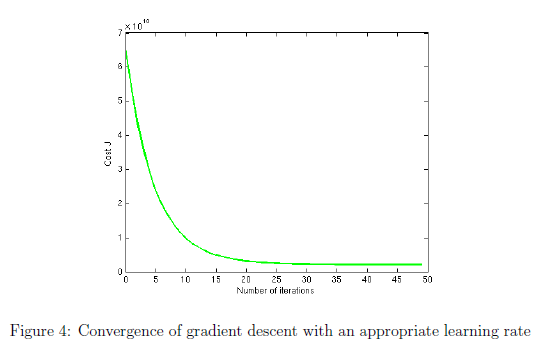

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

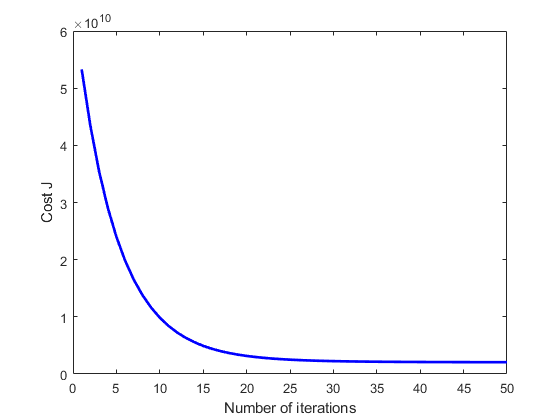

% Run gradient descent:
% Choose some alpha value
alpha = 0.1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
340412.659574
110631.048958
-6649.472950


% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================
X1 = [1650 3];
[X_nom, ~ , ~] = featureNormalize(X1);
X_nom = [1 X_nom];

price = sum(X_nom * theta);
%price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $423342.511917

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

Theta computed from the normal equations:
89597.909543
139.210674
-8738.019112

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

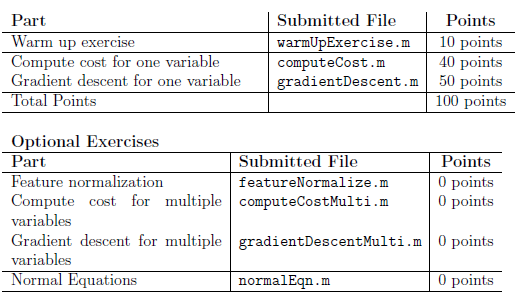

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.